# **Post Simulation Analysis using Machine Learning Models on the Data Obtained from MOBATSim **

The goal of this work is to build a collision predictor for all the crossway points in MOBATSim using machine learning models, the predictor should be able to predict the collision for road merges(shown in the figure left), Intersection has already protected automatically, so it’s not necessary to protect them. There mainly three parts: train a collision predictor, implement the collision predictor and evaluate predictor(figure right), the first two parts will be mentioned in the implementation part and the last part will be mentioned in the validation part. Firstly, some scenarios will be defined to find useful features and collect the data, then different classification methods from machine learning will be used to train some models for making predictions, the models will be evaluated, if the model is not suitable, we need to improve the way to collect more useful data, if the model is suitable, it will be used for a predictor for the general situation, which should be able to protect all the crossway points in MOBATSim.

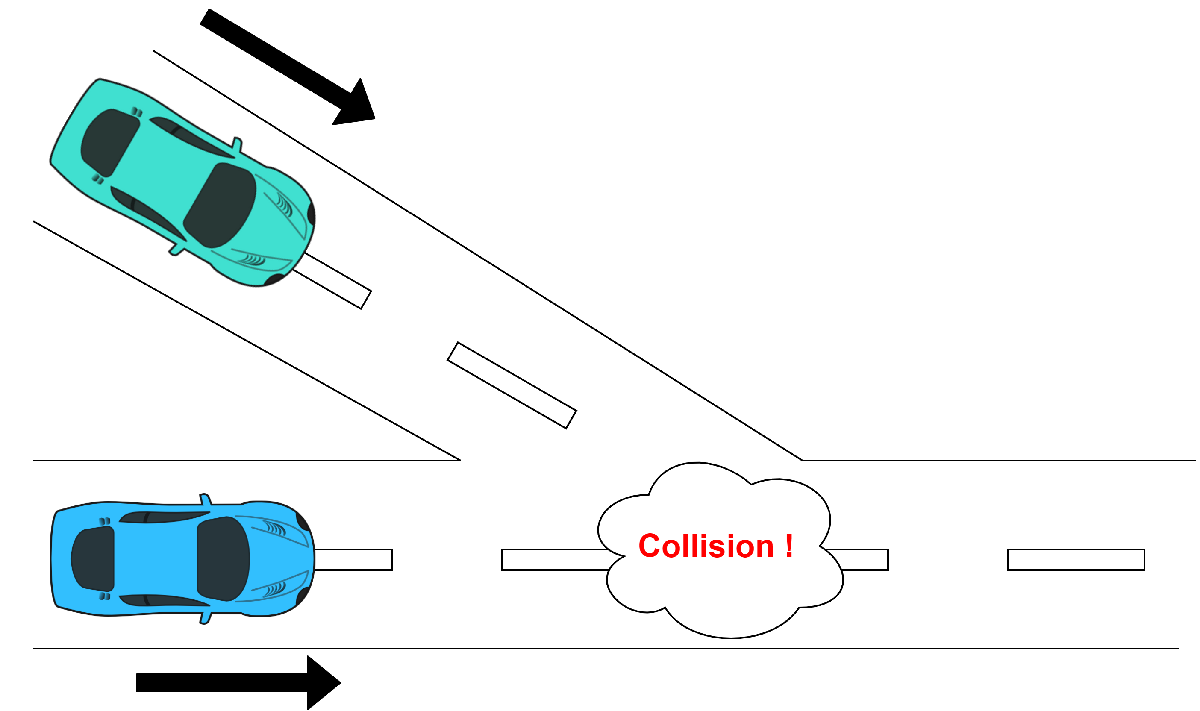                                                 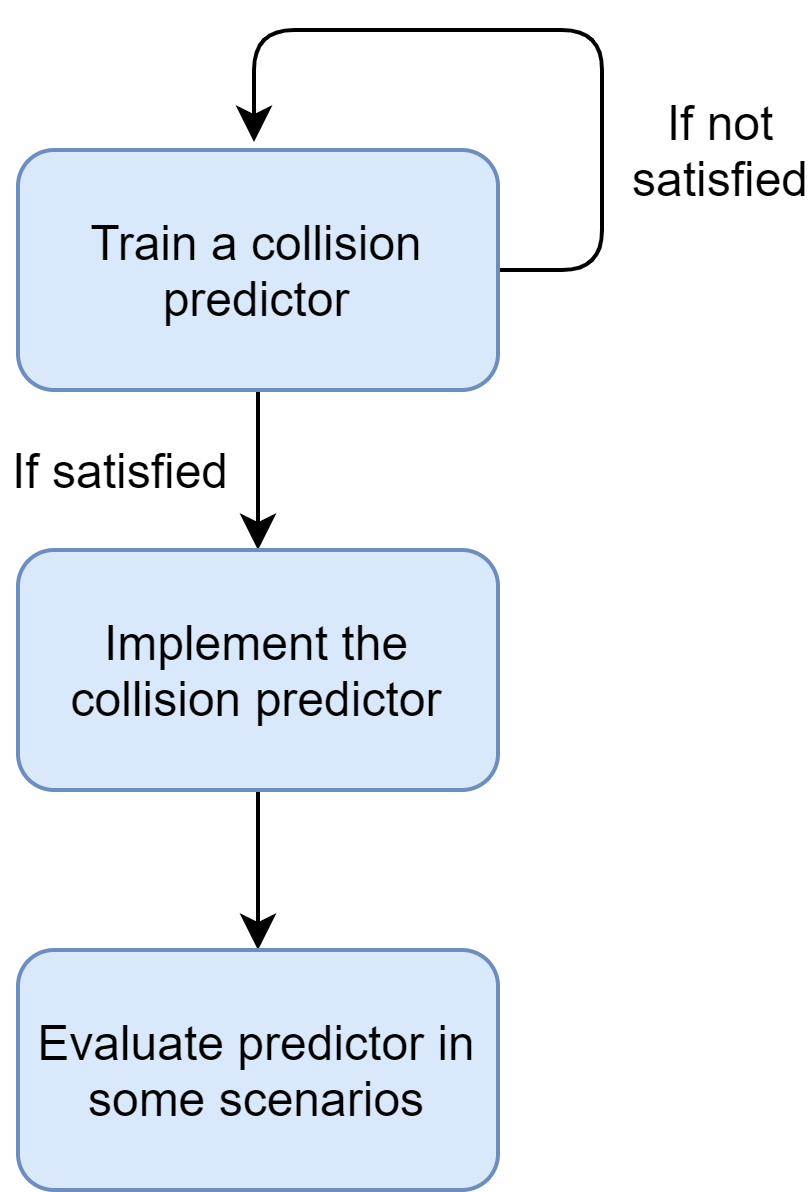

# **Documentation Structure**

Here is the structure of this documentation:

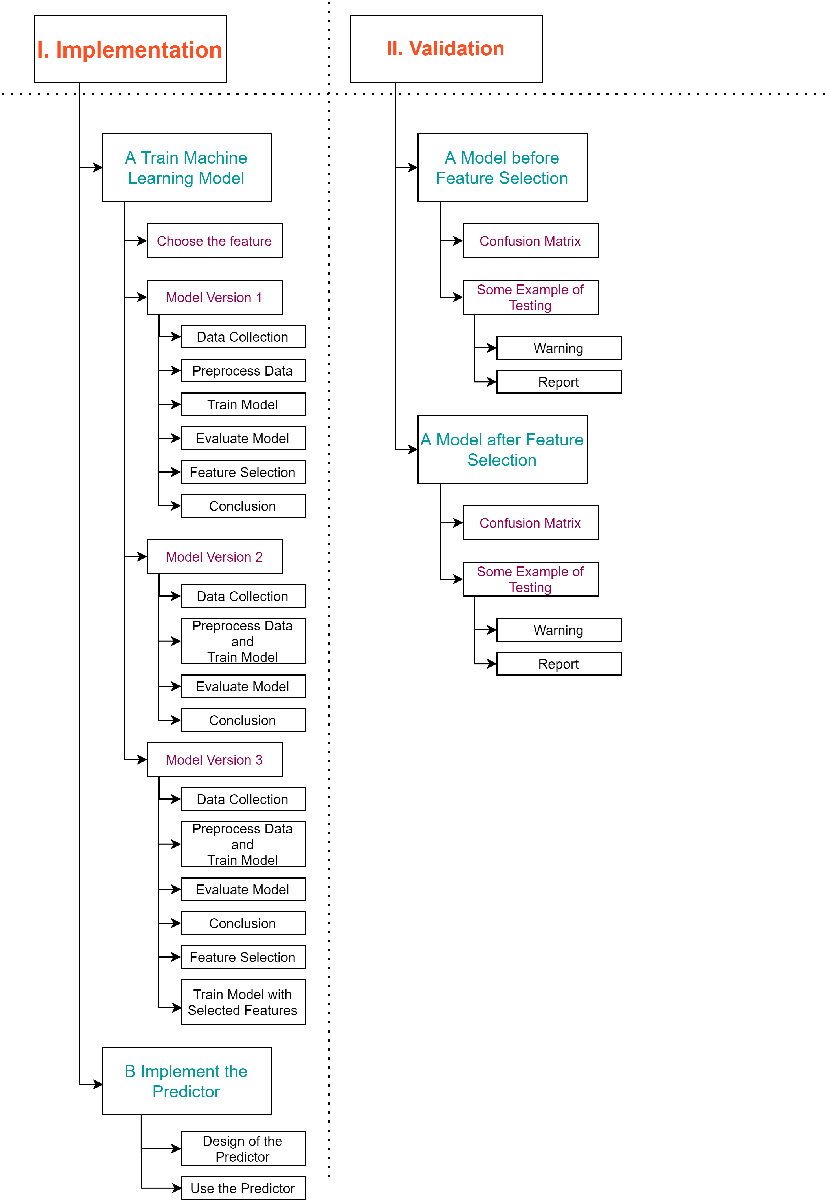

# **Table of Contents**

currentPath = pwd;

# **I. Implementation**

## **A Train Machine Learning Model**

This part is used to get the suitable machine learning model for the collision predictor. The workflow of this part is shown below:

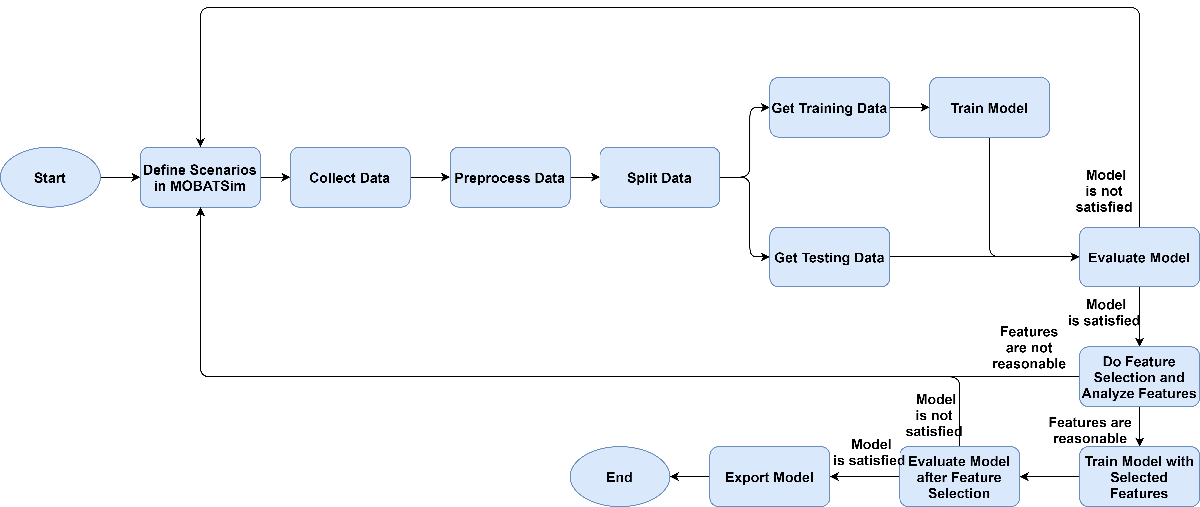

To go back to Table of Contents

### **1. Choose Features**

Firstly, we need to judge which features are important for the collision prediction in a road merge and make sure if we can also obtain them in MOBATSim. For merge collision, I think speed and position will be important, maxSpeed and minDeceleration are relative to speed, startingPoint, destinationPoint, currentRoute, ABEdistance are relative to position, so they should also be considered, besides, frontSensorRange may also be important for the collision. The Position data is a vector with 3 three values, so using the distance between position and crossway point instead of Position might be better to reduce the requirement of calculation and more relative to the merge collision. In summary, the following features are considered: maxSpeed, frontSensorRange, ABEdistance, minDeceleration, startingPoint, destinationPoint, currentRoute, Speed, DistancetoCrosswaypoint.

Before training this model for the general situation, which can be able to protect all the crossway points in MOBATSim, I have done some experiments in some test scenarios to check if the considered features make sense for collision prediction.

Here are some short introduction of the test scenarios:

- Test scenarios 1: All the vehicles run randomly, use maxSpeed, frontSensorRange, ABEdistance, minDeceleration, startingPoint, destinationPoint, currentRoute as features, and all these data will be collected after simulation. The result is not satisfied, I think it's because there are not dynamic features here, the only feature that would change is currentRoute, but since it would only be obtained after simulation, it will not be so useful. Besides, since the vehicles run randomly, it is not so effective for merge collision.

- Test scenarios 2: According to the result of Test scenarios 1, I try to add dynamic features and focus on Crossway point 11 for 2 vehicles(as figure shows). The features are maxSpeed, frontSensorRange, ABEdistance, minDeceleration, and the Speed and DistancetoCrosswaypoint of both vehicles when both vehicles have passed their critical points. The workflow is shown in the figure right. The result is satisfied.      

                        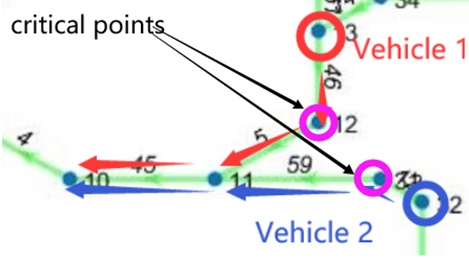                     

                               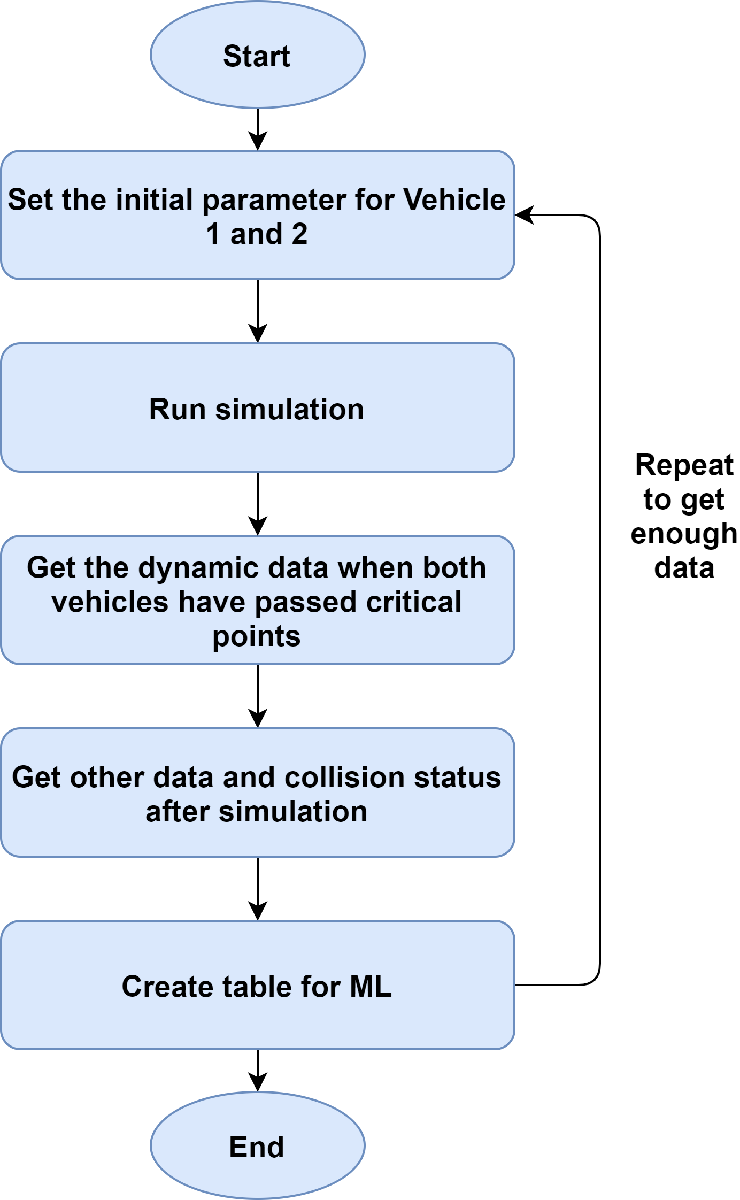

- Test scenarios 3: the last test show good result, so I try to extend it with more crossway points, I use to try to train the model for 4 crossway points and each crossway point with 2 vehicles as Test scenarios 2. The features are the same as Test scenarios 2, Waypoint 9, 11, 13, 44 will be used as crossway points for testing(see figure), and I use Vehicle A and Vehicle B instead of Vehicle 1 and Vehicle 2, Vehicle 1, 3, 5, 7 are Vehicle A and Vehicle 2, 4, 6, 8 are Vehicle B, then more data with different Speed and DistancetoCrosswaypoint, the workflow Test scenarios 3 are shown in the figure left. The result is satisfied but can still be improved, I think it's because of the path for vehicle 7 too long and there are not critical points in that path by the old version MOBATSim when I do this test.

- Test scenarios 4: It is similar to Test scenarios 3, Waypoint 9, 11, 13, 44 will be used as crossway points for testing. The data will be obtained when the simulation time is 2s, 2.5s, 3s, 3.5s, 4s, 4.5s, 5s, 6s so that more dynamic data can be obtained, the workflow is shown in the figure right. The result is satisfied.

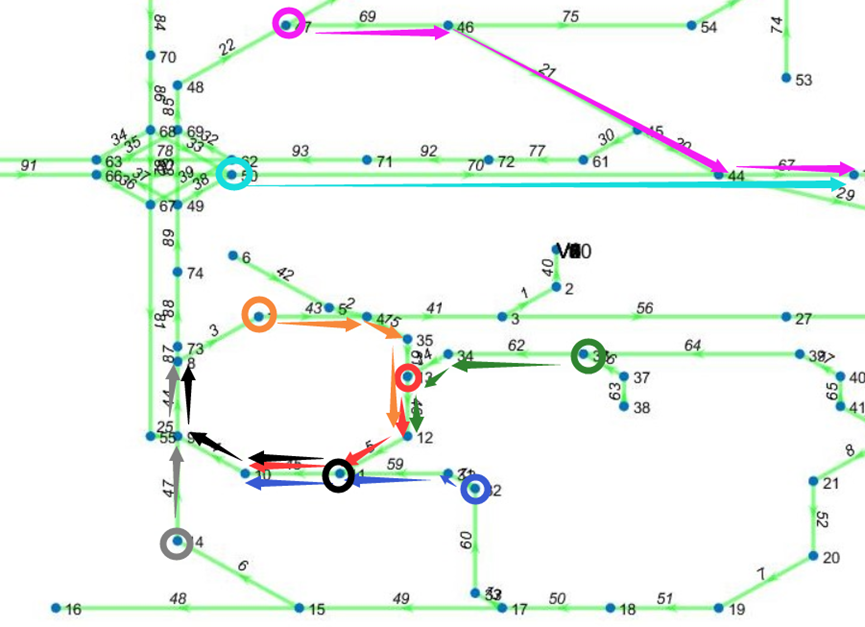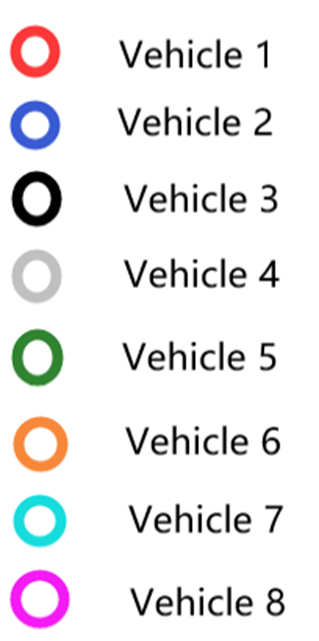

                                          Test scenarios 3                                                                                                                                 Test scenarios 4

                   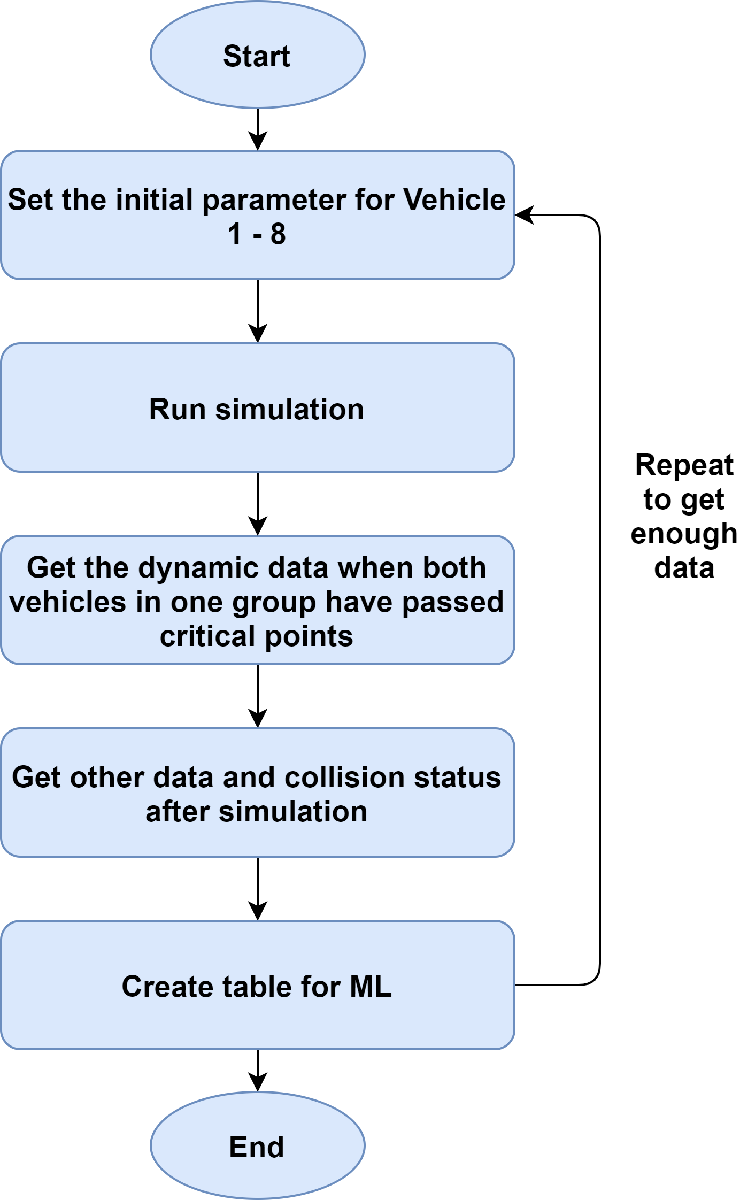                                                                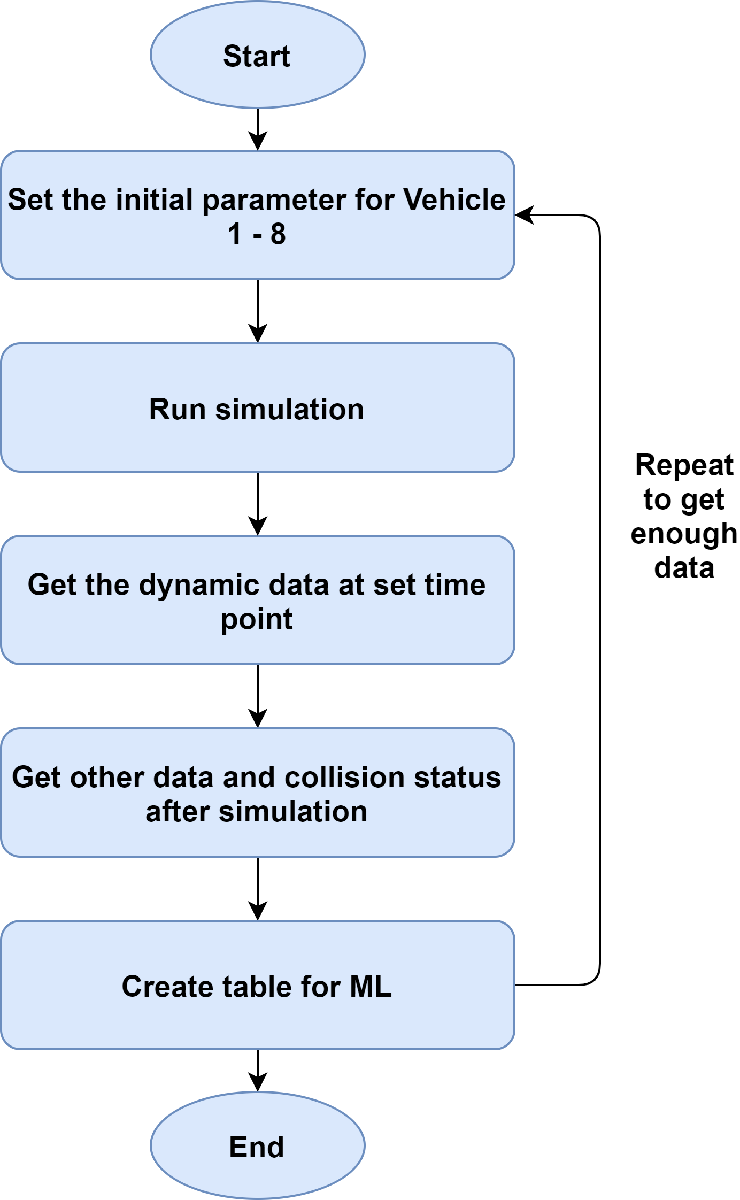

According to those test, the following features are chosen for collision predictor: 

- maxSpeed

- frontSensorRange

- ABEdistance

- minDeceleration

- Speed

- DistancetoCrosswaypoint

We collect data of these features from two vehicles in a group(when both vehicles are before the same crossway point) to create a table for machine learning.

To go back to Table of Contents

After the features are determined. We should find a way to collect data. The crossway point that we need to protect are Waypoint 11, 9, 13, 44, 4, 52, 36, 25, 23, as the figure shows. The intersection is protected automatically by an algorithm in MOBATSim, so we don't need to protect them.

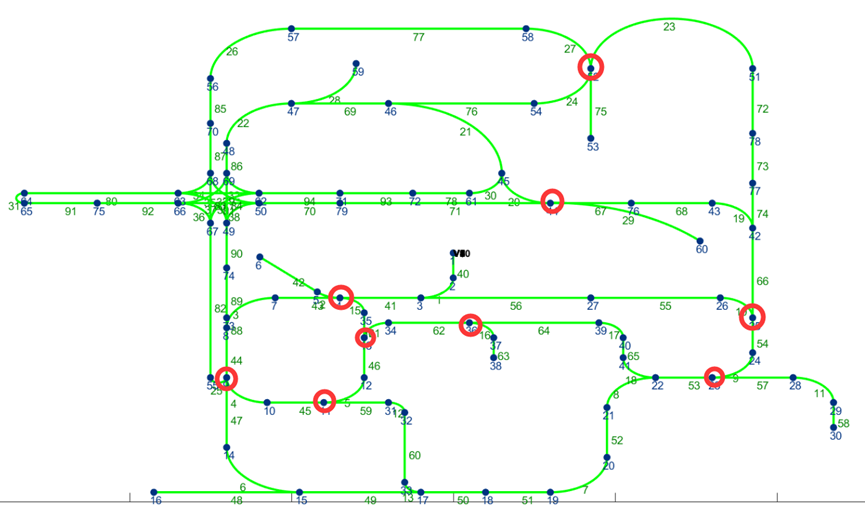

To go back to Table of Contents

### **2. Model Version 1 **

#### **Data Collection**

This part includes define scenarios and collect training data. 

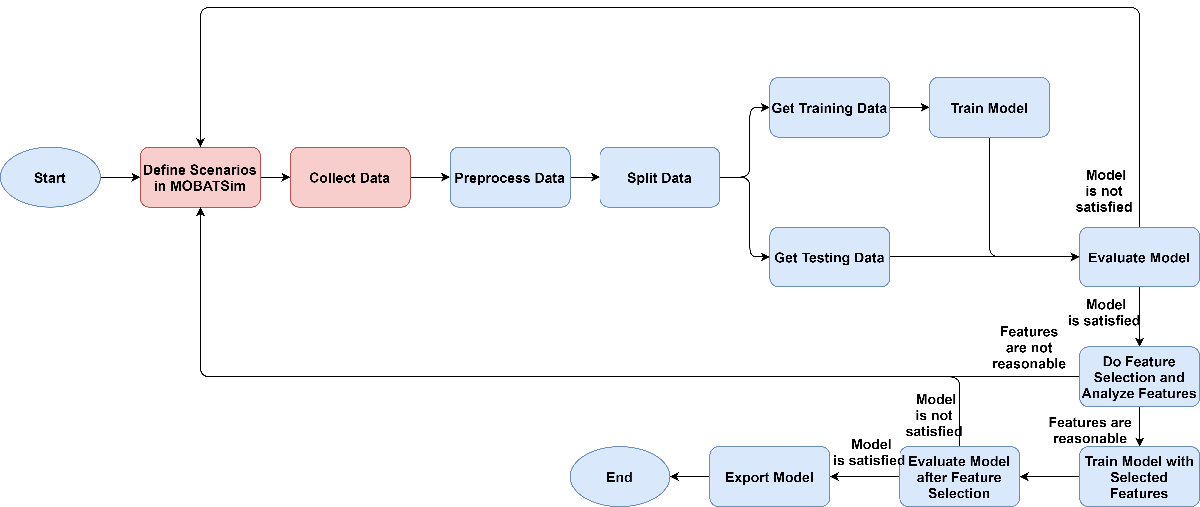

The workflow of data collection for this version is shown in the figure.

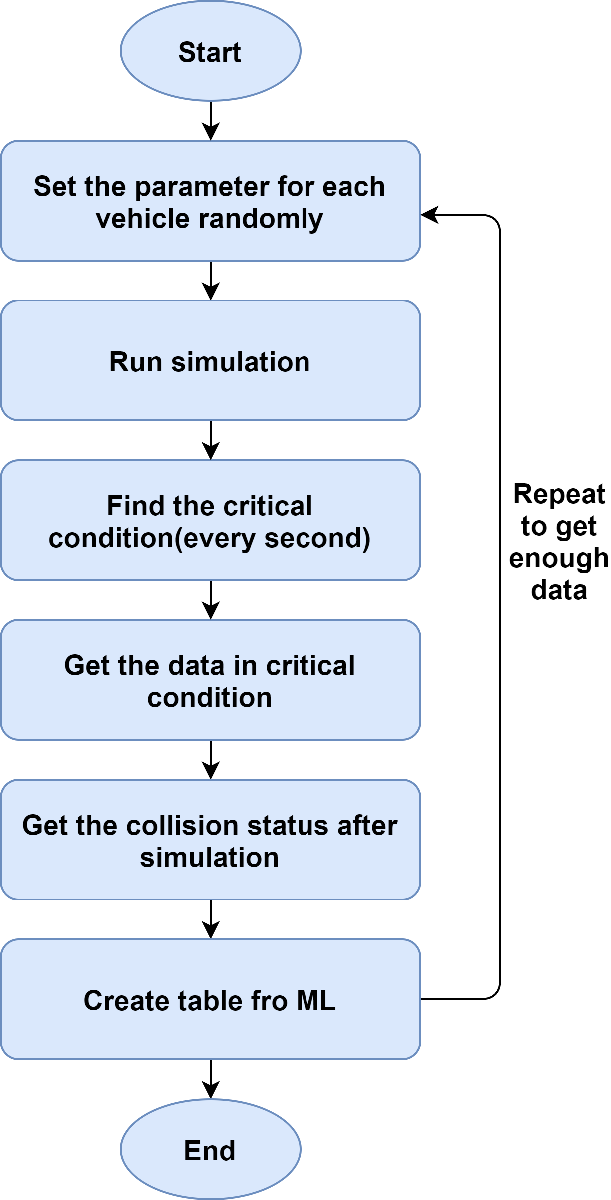

In the test scenarios(2, 3, 4) above, the startingPoint and Destination for each vehicles are fixed, as a result of that, the path for each vehicle are also fixed, but in general, the startingPoint and Destination and the path for vehicle have many different possibilities, to let the predictor work well in as much as possible scenarios, we need data in many different situations, one way to do that is set the parameter of vehicles randomly (including startingPoint, Destination, maxSpeed, frontSensorRange, AEBdistance, minDeceleration) like the test scenario 1, the related code is here. The result of test scenario 1 is not good, some important reasons for that may be:

- The dynamic features are not involved

- It doesn't focus on the road merge(crossway point)

So we have to solve this two problems, for the first one, we have determined the features in the choose features part, for the second problem, we should find a way to find the situation, in which we need to make a prediction, that means we need to focus on the crossway points we need to protect.

Since we need to collect the dynamic data during the simulation and we don't know which vehicle will arrive at which crossway point, we need to set a trigger to find out the critical condition. 

The critical condition is that 2 vehicles in the different paths before a crossway point and run to the crossway point. 

To find out the critical condition, we can think of a crossway point simply as the figure shows, the different paths before the crossway point can be defined as Path A and Path B(Figure left), when we find the critical condition, firstly we check the currentRoute of Vehicle 1 to Vehicle 10, if one of the vehicles is on the Path A of a crossway point, then we check the currentRoute of Vehicle 1 to Vehicle 10 to see if there is another vehicle on the Path B of the same crossway point. If both Path A and Path B of a crossway point have vehicles, then it is a critical condition, in this case, we can get the data from both vehicles. The data includes maxSpeed, frontSensorRange, AEBdistance, minDeceleration, Speed, and Position of both vehicles, the Position data will be used to calculate DistancetoCrosswaypoint, and we can use these data to create a table, besides, we also need to get the ID of the vehicle, because we need to connect the data we get here with the collision status of the vehicle at the end of the simulation. For the critical condition, we should use the "currenRoute" of vehicles rather than "Lastwaypoint", because for some waypoint, "Lastwaypoint" will cause an error, for example, Waypoint 4(Figure right), if we use "Lastwaypoint 4" as a critical condition, it means not only path 15 but also path 41 will be selected.

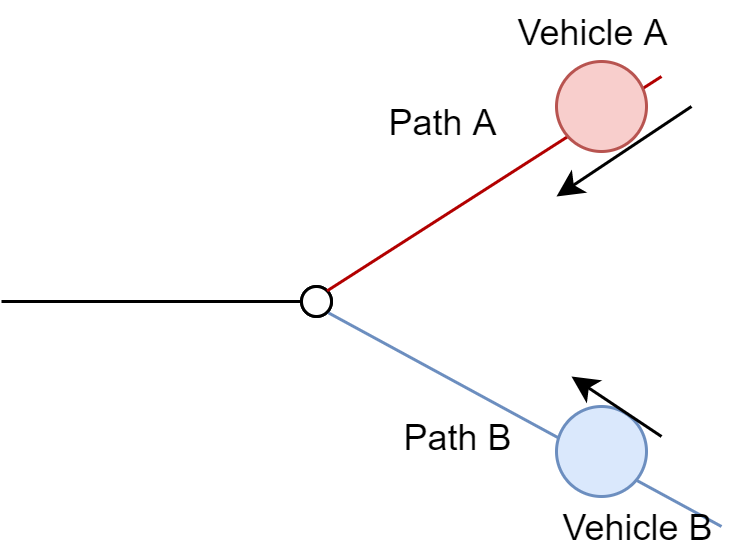                                                              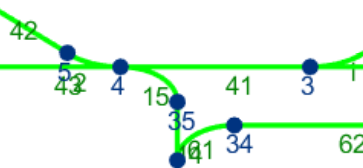

An example of finding critical condition is:

The trigger should not be work all the time, or it will slow down the simulation speed, we can set a sampling time as 1 second, so the predictor will check the critical condition every second and collect the data. The related code is here.

After the simulation, we will get the collision data of each vehicle, and according to the Vehicle ID, we can match the collision data with the data we get before. In the end, we delete the Vehicle ID in the table and get the finial table for machine learning. The related code is here.

There are 4 files for data collection, the related files are in:

cd(currentPath + "\TrainModel\Version1\DataCollection")

- **Version1_scenarios.m** is the file for setting the initial values, we set the initial value randomly in this case.

- **CollisionPredictorV1.m** is the file for collecting the data during the simulation, when we use this way to get the data, we need to change line 11 in infrastructure.m to load this file.

- **Version1_preprocess.m** is the file for creating the table for machine learning, it obtains the collision data after the simulation, and it also deletes the Vehicle ID for the table created in CollisionPredictorV1.

- **Version1_run.m** is the file that set a loop for collecting the data so that we can get a large number of data easily.

The dataset I got is

cd(currentPath + "\TrainModel\Version1\Data")
load('Data.mat')

To go back to Table of Contents

To go back to Implement the Predictor

To go back to Validation for Predictor before Feature Selection

#### **Preprocess Data**

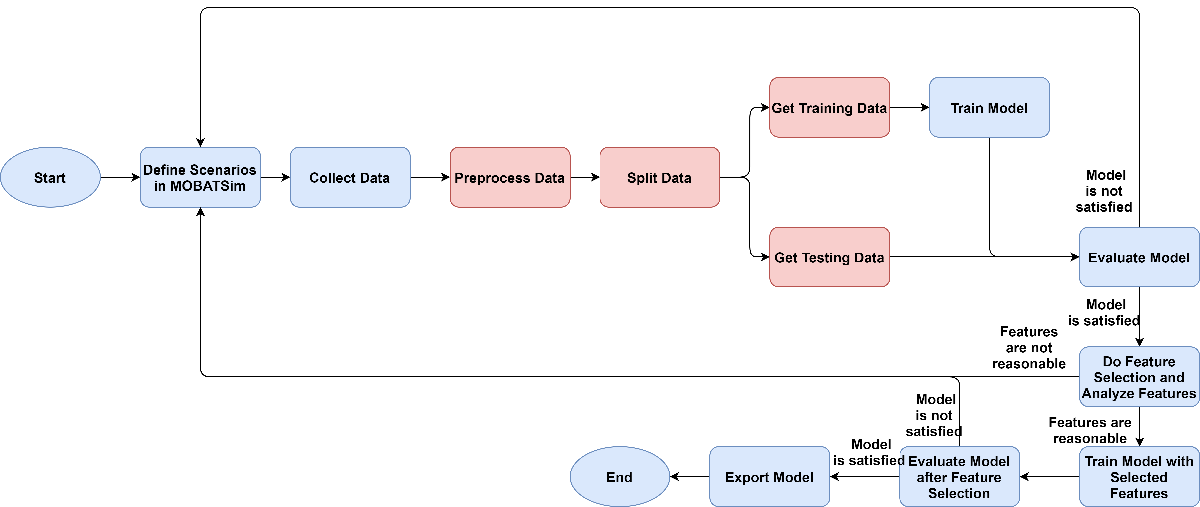

Usually, preprocess data includes standardization and transformation of the data type, and after that, we can divide the dataset into training data and testing data.

**Standardization**

The goal of standardization is to scale the data so that all the features can be treated equally, it is important for some of the algorithms. The formel of standardization is:


$$x\prime =\ \frac{x+\bar{x} }{\sigma }$$


$x\prime$* ...* the new data, 

$x$ ... the original data, 

$\bar{x}$ ... the mean of each rank of the data,

$\sigma$* ...* the standard deviation of each rank of the data.  

In the test scenarios, I've done standardization and compare the result, I found that for the features we used, doing standardization or not doesn't make much difference, that means the scales of each feature are similar, so we don't need to do it.

**Transformation of the Data Type**

For machine learning, there are usually two types of variables: categorical data and numerical data. For some algorithms, we need to convert the data type so that all the features are in the same type. In our case, all the data are numerical data, so we don't need to do it.

In summary, in our case, standardization and transformation of the data type are not necessary.

**Divide Data**

For evaluating models later, we can divide the whole data that we've collected into training data and testing data, we use the training data to train the model and use the testing data to evaluate the model. The related code is shown below:

The related data are in fold

cd(currentPath + "\TrainModel\Version1\Data")

To go back to Table of Contents

#### **Train Model**

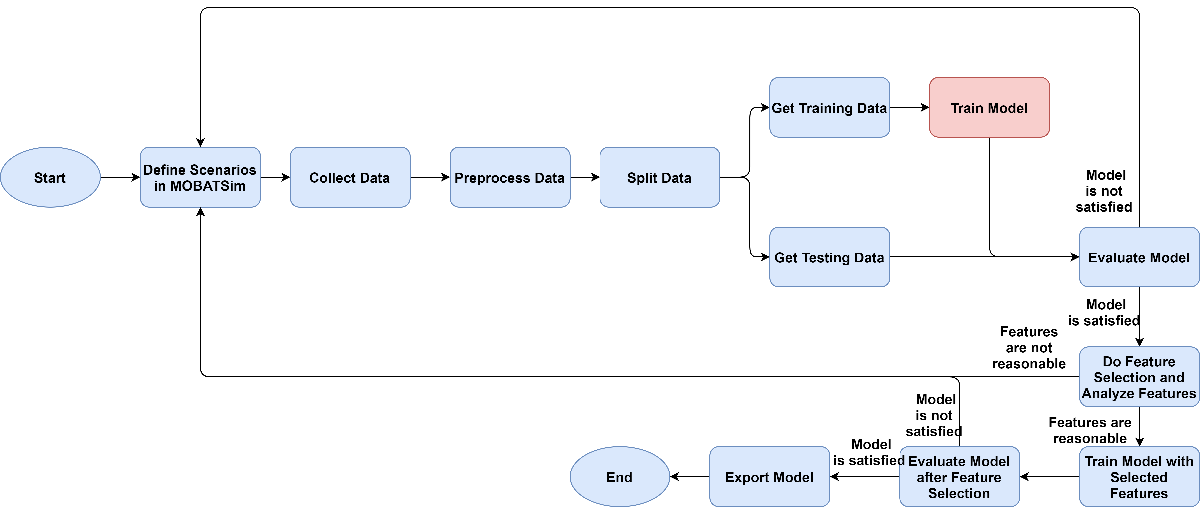

Now we can use the data to train models, for collision prediction we need to use classification algorithms, because the response(output) is collision, which has 2 class(collide/not collide), it's a finite and discrete output, in this case, classification will be suitable.

For collision, we use "1"  to represent collide, "0" to represent not collide.

To get a good estimate of the models, we use 10-Fold cross-validation here. (To learn more about a cross-validation click [here](https://www.mathworks.com/discovery/cross-validation.html))

The following classification methods will be used:

-  Decision Tree

-  Ensemble

-  K-Nearest Neighbor(KNN)

-  Logistic Regression

-  Support Vector Machine(SVM)

-  Naive Bayes

-  Discriminant Analysis  

To learn more about classification algorithms click [here](https://www.mathworks.com/help/stats/classification.html).

For tuning the hyperparameters of the models, we use Bayesian optimization and set the iteration to 100 so that the iteration time is enough to find out a suitable hyperparameter. (To learn more about optimizer click [here](https://www.mathworks.com/help/stats/hyperparameter-optimization-in-classification-learner-app.html).)

In MATLAB, we can train the classification model using code with the function already set in MATLAB, or we can use the Classification Learner APP in MATLAB, here I use the Classification Learner APP.

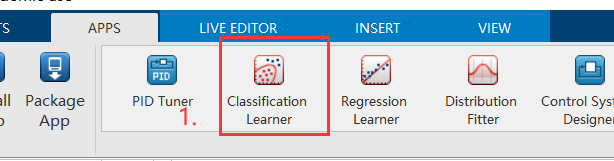

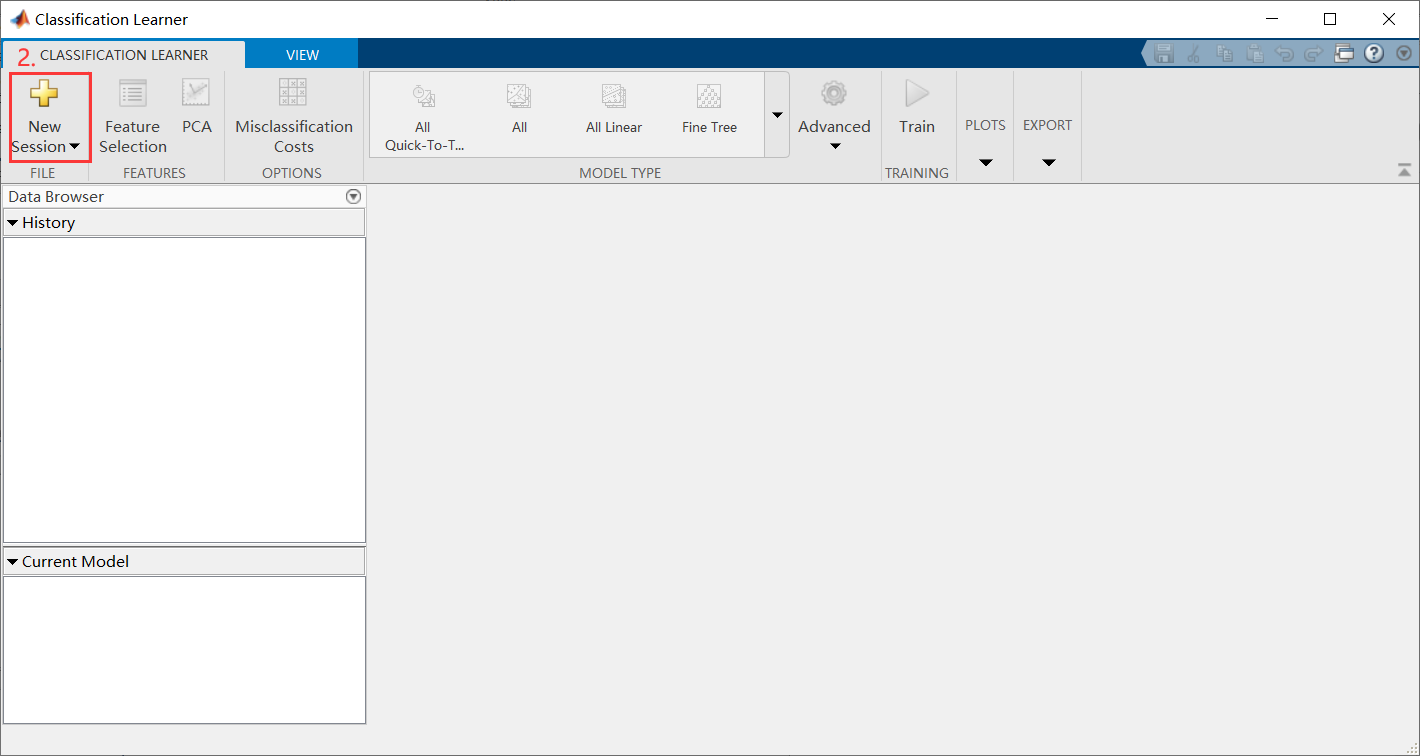

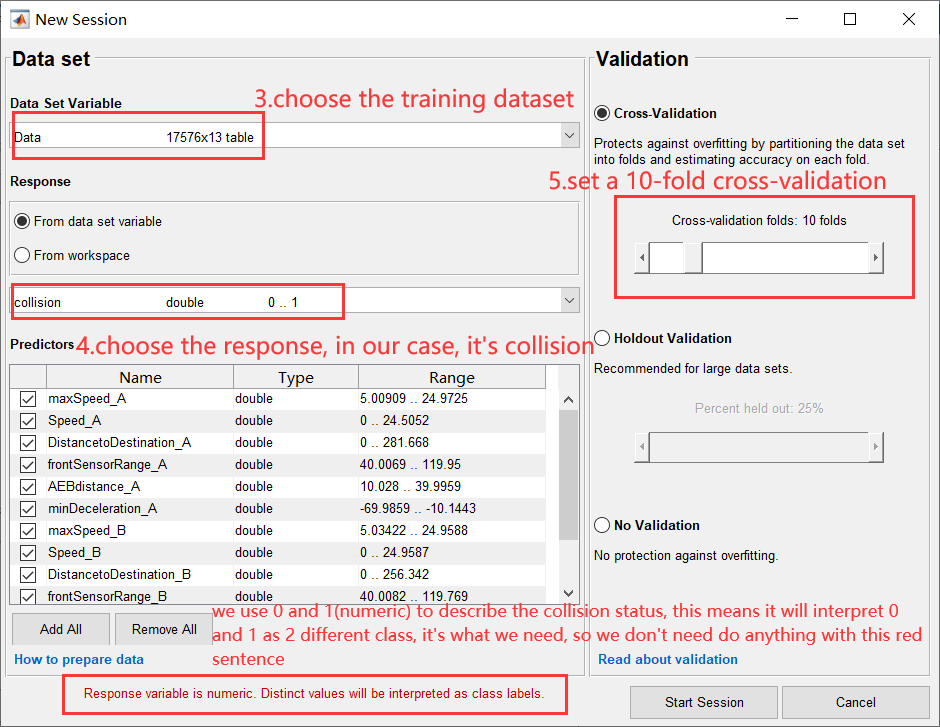

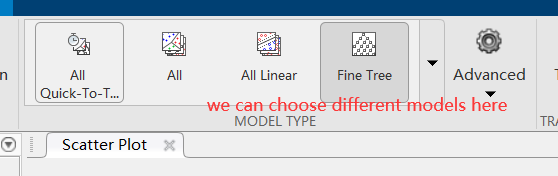

we can try all the models with the optimizable one so that we can get the best model.

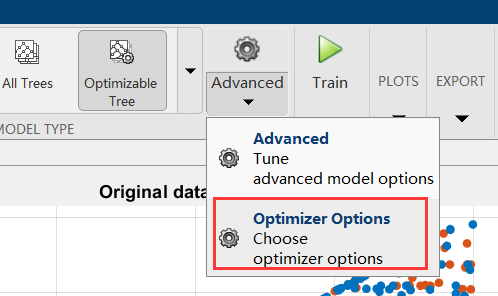

when we use the optimizable model, we can set the optimizer option.

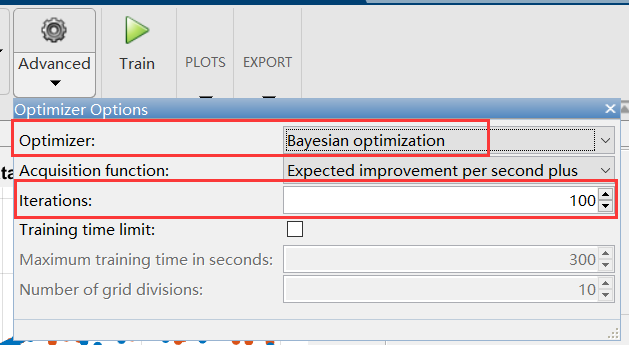

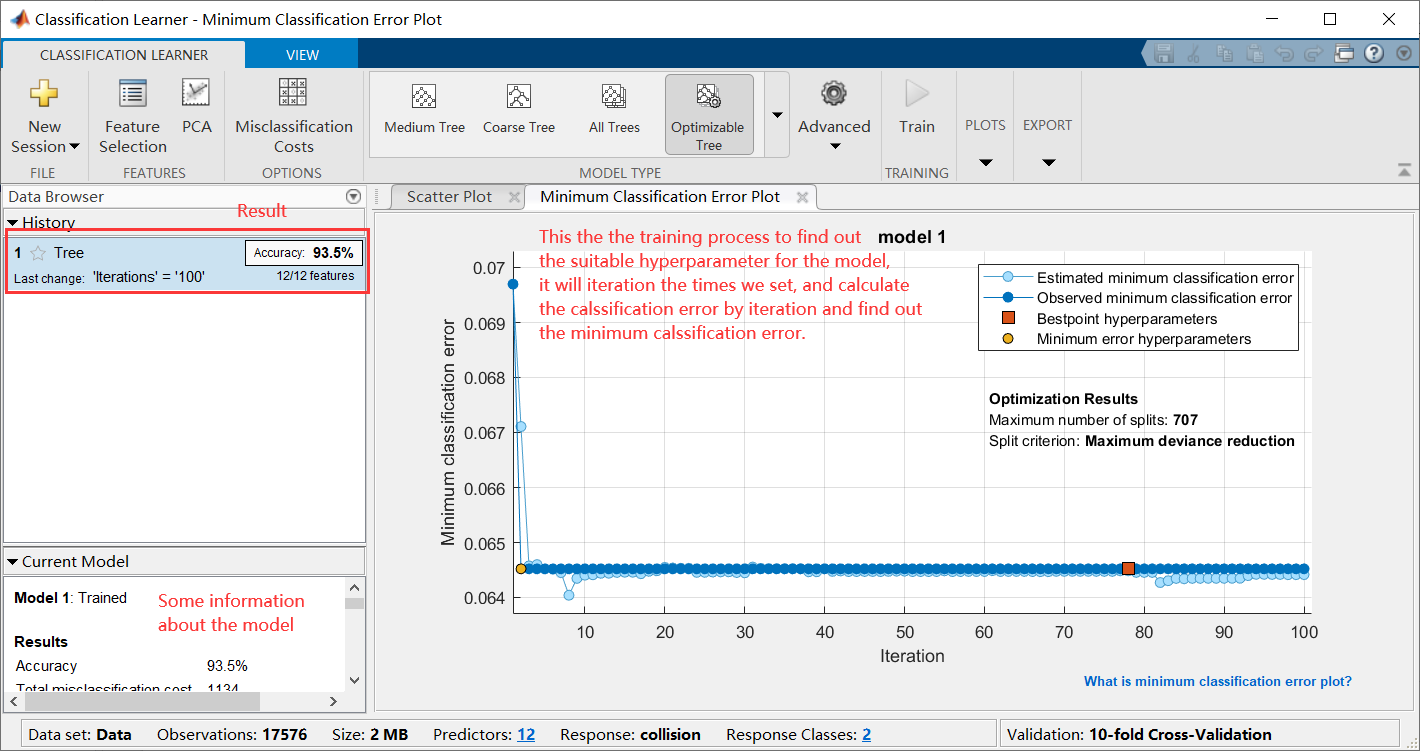

Here we can use Bayesian optimization and set the iterations to 100 to ensure that the iteration time is enough to find out a suitable hyperparameter, then we can click train and train the models.

To go back to Table of Contents

To go back to Preprocess and Train Model(Version 2)

To go back to Preprocess and Train Model(Version 3)

To go back to Train Model with Selected Features(Version 3)

#### **Evaluate Model**

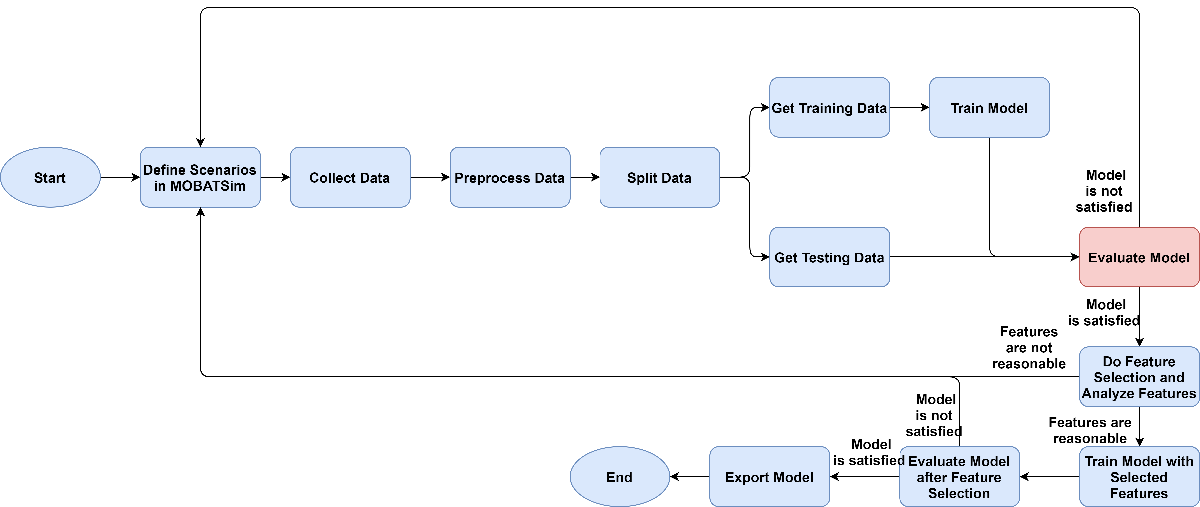

The accuracy of the models is shown in the figure below, this accuracy is calculated by validation data(we use 10-fold cross-validation for training the model) The accuracy is very high by training the model, Random Forest(Ensemble of tree) shows 99% accuracy, it is enough for the collision predictor.

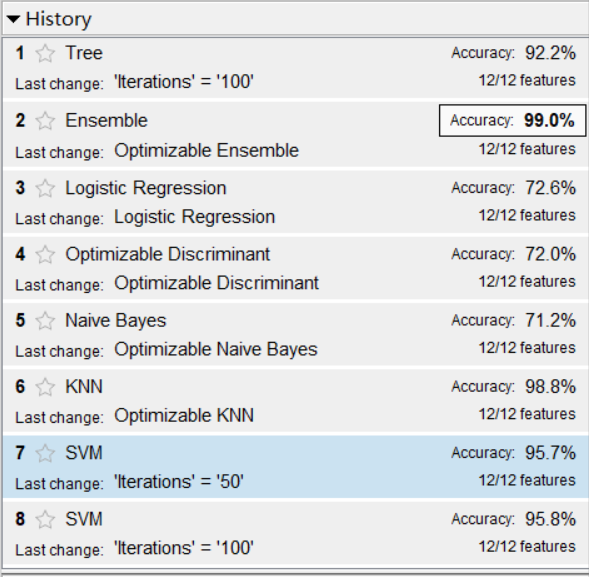

We export the random forest model, and test it with the testing data, 

[Predict,~] = predict(trainedModel.ClassificationEnsemble,dataTest);
acc = nnz(Predict == dataTest.collision)/ numel(dataTest.collision)

the accuracy is also good(99.2%), so this model might be useful.

To go back to Table of Contents

#### **Feature Selection**

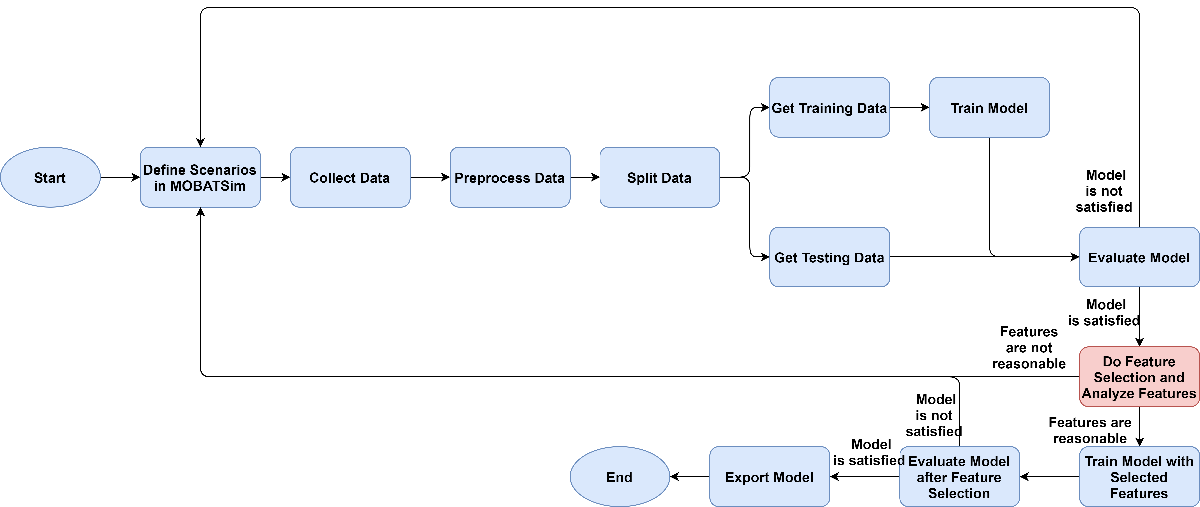

Since we use the Random Forest model, we can do the feature selection with the importance of features in Random Forest. (To learn more about a feature importance click [here](https://www.mathworks.com/help/deeplearning/ug/object-detection-using-yolo-v2.html?s_tid=blogs_rc_6)) , you can use the following code to create bar chart or Pareto chart

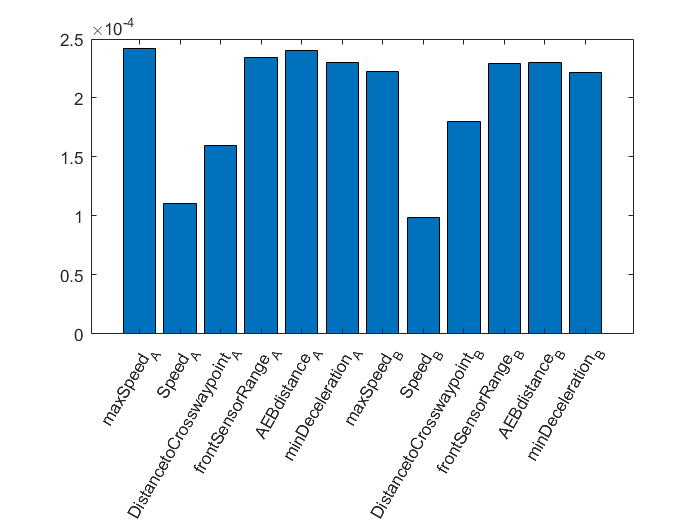

p0 = predictorImportance(trainedModel.ClassificationEnsemble);

%bar chart
bar(p0)
xticklabels(Data.Properties.VariableNames(1:end-1))
xtickangle(60)

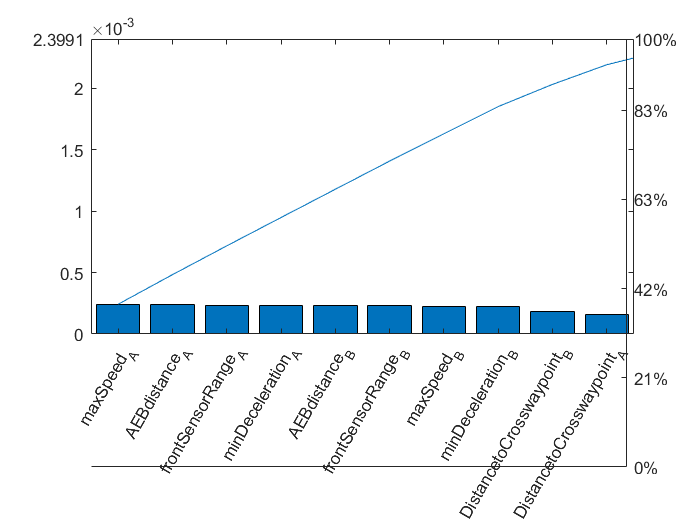


% pareto chart
pareto(p0,Data.Properties.VariableNames(1:end-1))
xtickangle(60)

Then we can use the Pareto chart to compare the importance of features, the Pareto chart shows that most of the features have similar importance, this result is not as expected, in the previous tests, we can find that Speed and DistancetoCrosswaypoint play important roles in collision prediction, which is completely different from this result, so the result may be problematic.

To go back to Table of Contents

To go back to Feature Selection(Version 3)

#### **Conclusion**

This model has a problem with feature selection, the speed and position don't play important roles as expected. And by using this model to predict, I find that this model doesn't perform well in the real situation.

The problems above may be due to the following reasons:

1.  We get the data every second before a crossway point,  so we get the data many times when two vehicles are approaching the crossway point,  all static data will stay the same value, for example, when we get the data 3 times, the maxSpeed maybe 8.1489 for all the 3 times(same to the other static features), but the Speed and DistancetoCrosswaypoint will keep changing, and for all this 3 rows data, the collision status is also the same(for example "1" for 3 times), so it might increase the importance of the static features and reduce the importance of the dynamic features.

2.  There is a lot of data with a speed of 0 in the data set. The situation may be that the vehicle has collided or reached the destination when entering the path before the crossway point. Since the vehicle is already in the critical condition, these data will be recorded, and because the vehicle is no longer moving, such data will be obtained every second and many times,  and it will interfere with the training of the model. And due to a large amount of such data, the accuracy of training is very high, but the performance is not ideal when the model is used.

3. The collision data is obtained at the end of the simulation, which is the final state of the vehicle. This will also affect the accuracy of the model. In actual operation, the following situations may occur:

- A vehicle has passed two or more crossway point, it did not collide at the previous crossway points, but collided at the last crossway point. The data of collision will be "1"(collide) for the data from all crossway point it passes, but in fact, only the last one should be "1"(collide). There was no collision at the previous crossway points and the collision information for those data should be "0"(No collision). As the following figure shows, at the time t1, Vehicle 1 and Vehicle 2 are in a critical condition and they don't collide together, then at time t2, Vehicle 1 and Vehicle 3 collide together in another crossway point, since we get the collision data at the end of the simulation, the collision data of Vehicle 1 for both crossway point will be "1"(collide), but in fact, at the first crossway point, it doesn't collide.

              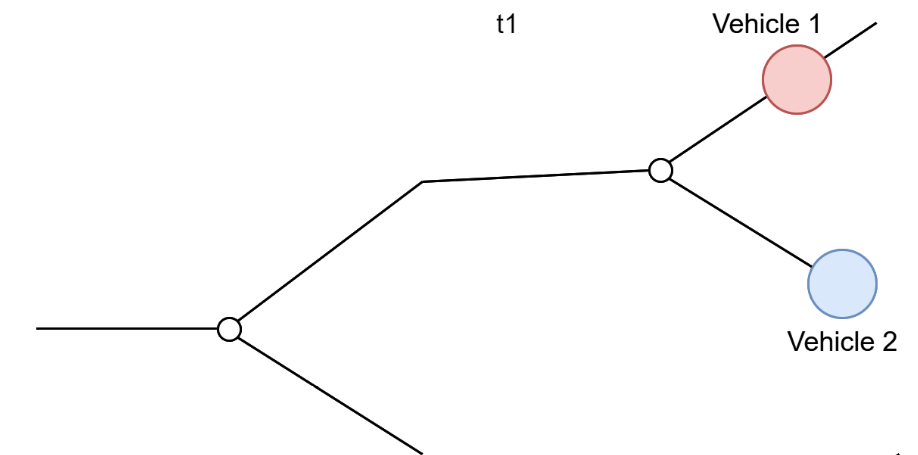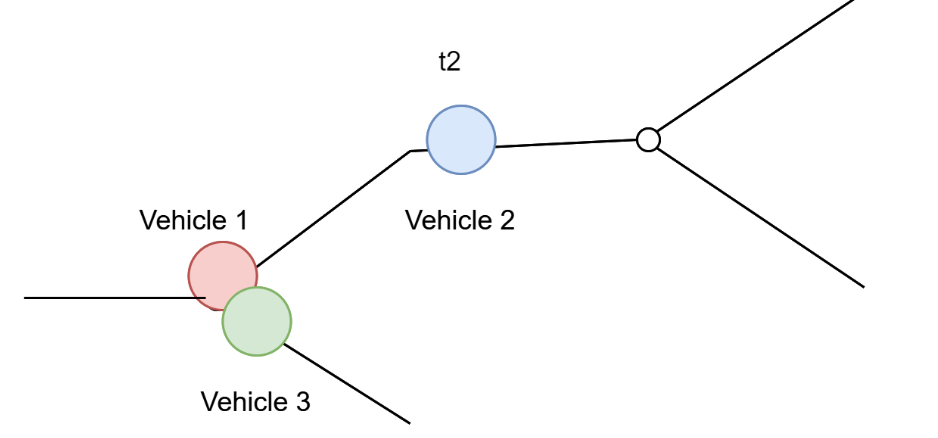

- A vehicle has been in the critical condition and doesn't collide there, but it collides somewhere else, for example, in many simulations, the vehicles collide in the straight road(as the figure is shown), and the collision data for such vehicles will also be "1"(collide) even if the vehicles don't collide at the crossway point, this collision is not what we focus on here.

                                                                               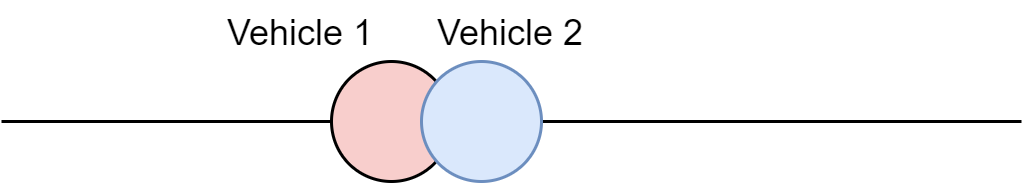

4. Crossway point 9 has 3 paths before, in this experiment, I set Path 4 as Path A, and the other 2 Path together as Path B(Figure left, in code 9A), in this way, a situation is lost, which is the vehicles in Path 55 and Path 47, so another critical condition should be added(Figure right, in code 9B). 

                              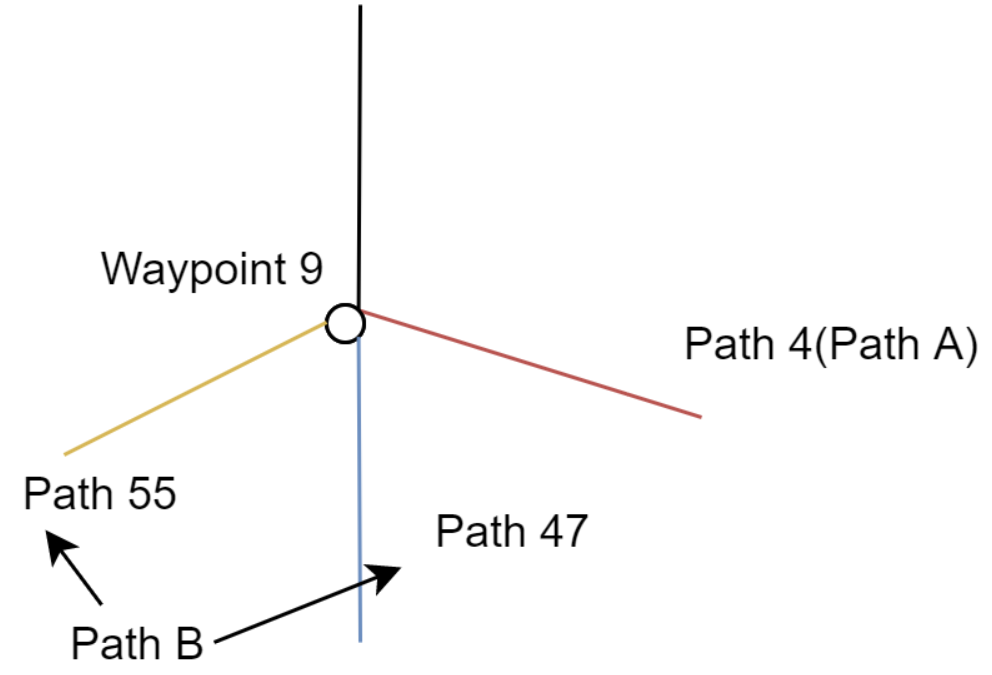                                        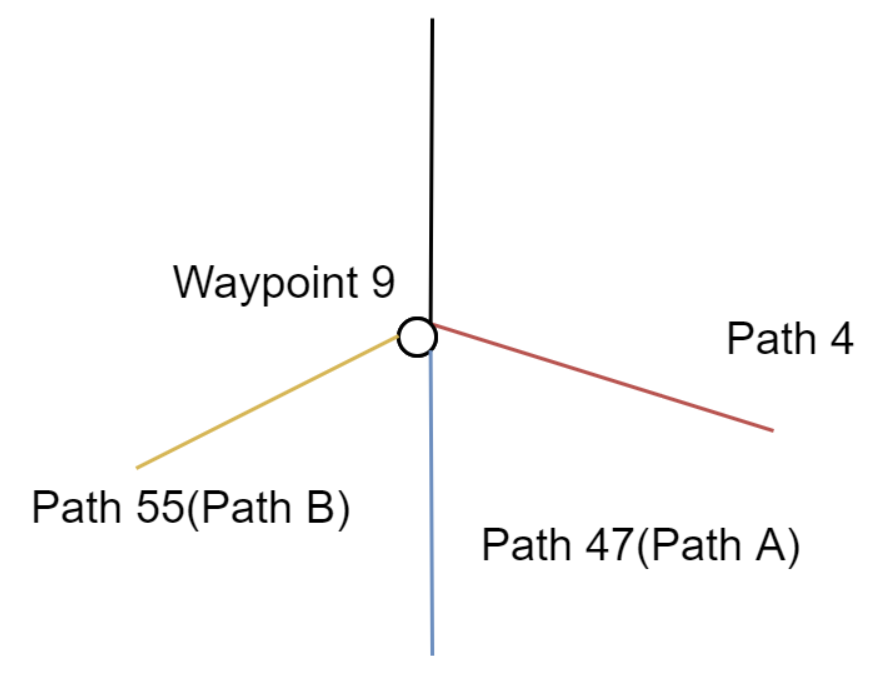

To go back to Table of Contents

To go back to Model Version 3

### **3. Model Version 2**

#### **Data Collection**

The workflow of this method is shown in the figure.

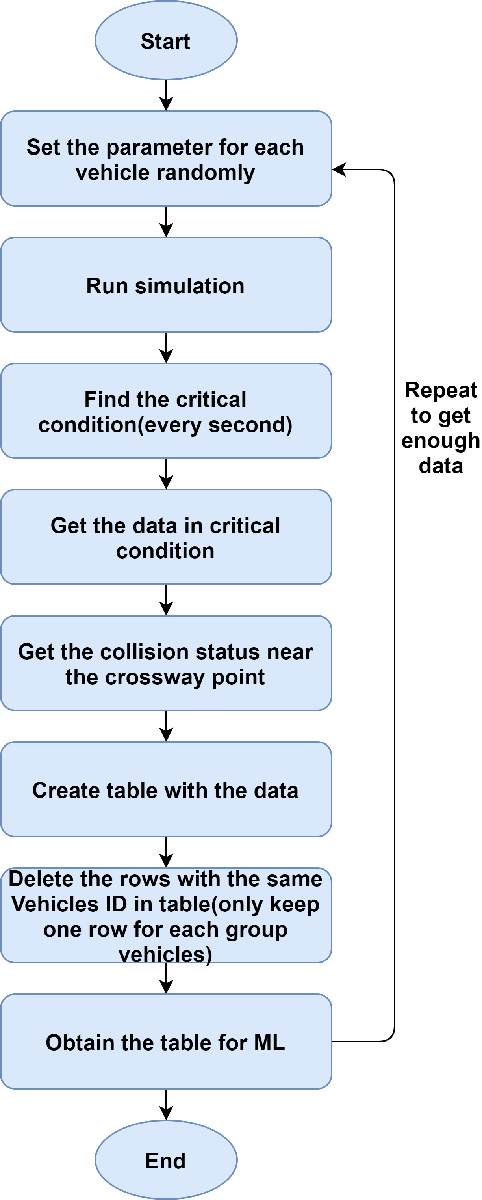

To solve the problem above, the following changes will be taken by collecting data:

- For the problem in feature selection, it might be useful to get the data only one time before the crossway point other than get the data every second before the crossway point(many times). One way to do this is to delete the data of the same vehicle group and only keep the first one data that the predictor gets. We can use the vehicle ID the check the table, if the Vehicle ID for both vehicles is the same for some rows, we can keep the first one and delete other rows. The related code is here.      

- For the data with a speed of 0, we need to add the speed isn't 0 in our critical condition, so that the data of the vehicles that already collided or arrived at the destination will not be collected in the dataset. Here is an example of crossway point 11:

-  For the problem of the collision data, we should get the collision data in an area near the crossway point. Like the red path in the figure. If we find that the collision status of both vehicles becomes "1"(collide) in such paths, we should set the collision data as "1" for that row data, otherwise, it will be "0". This process will be performed every second. 

                                                     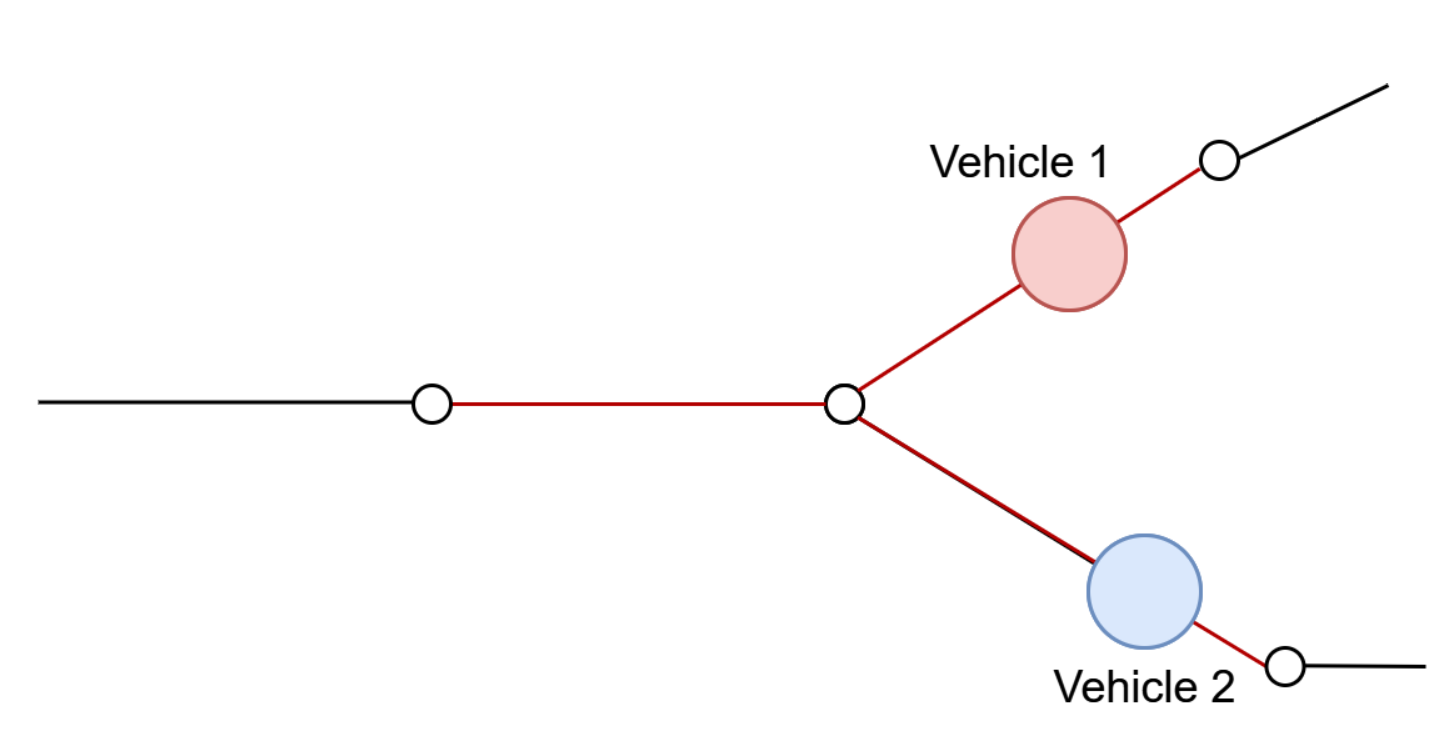

In this case, we use  "Lastwaypoint" of the vehicle instead of "currenRoute" to set the condiction, because using "Lastwaypoint" can cover all the possibility, let's take Waypoint 4 as an example when a vehicle passes the Waypoint 4, it might go on Path 41 or Path 15, using Lastwaypoint 4 can cover both situations.

                                                                   

The code example is below, for full related code click here:  

- Add the missing part of Crossway point 9. The related code is here.

There are 4 files for data collection, the related files are in:

cd(currentPath + "\TrainModel\Version2\DataCollection")

Version2_scenarios.m is the file for setting the initial values, we set the initial value randomly in this case.

CollisionPredictorV2.m is the file for collecting the data during the simulation, in this case, the collision data will also be obtained in this file, when we use this way to get the data, we need to change line 11 in infrastructure.m to load this file.

Version2_preprocess.m is the file for creating the table for machine learning, and it deletes the Vehicle ID for the table created in CollisionPredictorV2 and deletes the rows with same Vehicle ID.

Version2_run.m is the file that set a loop for collecting the data so that we can get a large number of data easily.

The dataset I got is

cd(currentPath + "\TrainModel\Version2\Data")
load('Data.mat')

To go back to Table of Contents

To go back to Model Version 3

#### **Preprocess Data and Train Model**

This part is similar with the corresponding part in Model Version 1.

To go back to Table of Contents

#### **Evaluate Model**

The accuracy is much worse than expected, the highest accuracy is 76.6%, so there might be some problems.

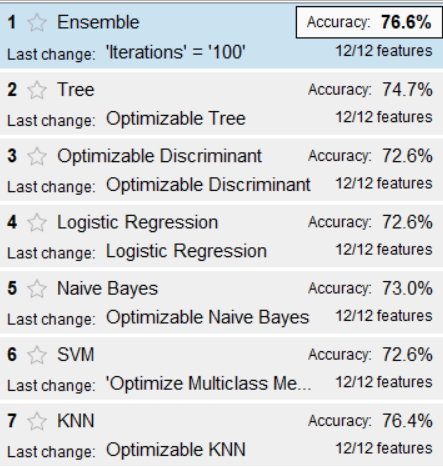

To go back to Table of Contents

#### **Conclusion**

The accuracy is not good enough, the main reason may be the situation when the vehicles randomly run is too complex, there are many different ways of collision that we don't focus on, the following situation may happen and they will affect the data:

- More than 2 vehicles are run to one crossway point, by randomly set run, in many cases, it's not the vehicles in Path A collide with the vehicles in Path B, the vehicles in Path A may collide with the vehicles in Path A, and since there are vehicles in Path B, this data will be collected, but it's not what we need. The figure left is an example by simulation, the figure right shows an example of the process: at time t1, 4 vehicles go into the critical condition, and at time t2, Vehicle 1 and Vehicle 3 collide together, Vehicle 2 and Vehicle 4 collide together, these data will be collected, but it's not the data we need, what we focus on is: if Vehicle 1 will collide with Vehicle 2 or 4 or not, and if Vehicle 3 will collide with Vehicle 2 or 4 or not.

                              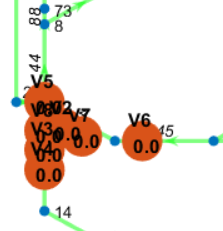                                   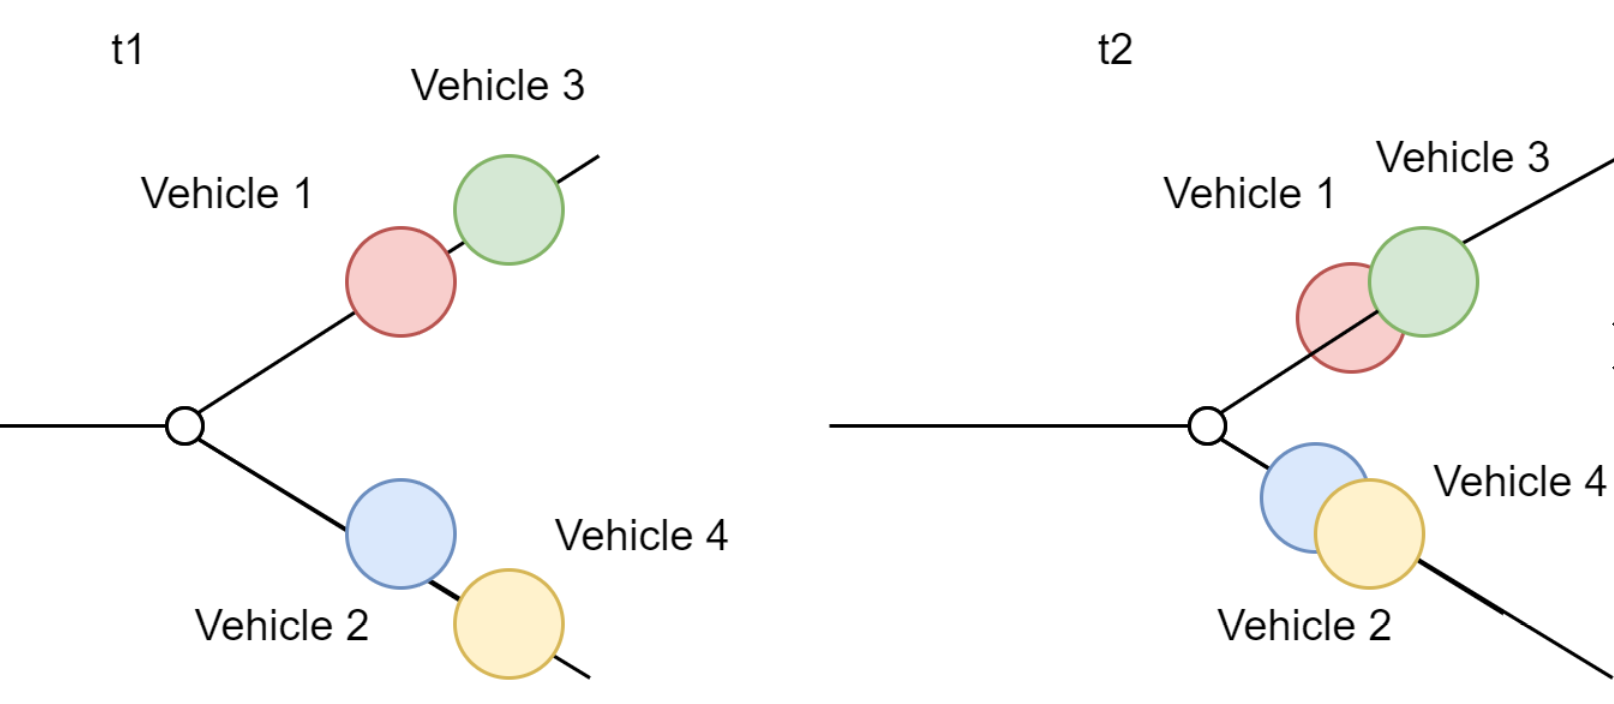                                                      

- The Destination of some vehicles are just in the critical paths when they stop there, the vehicles come later may not be able to pass the crossway point, but the data of the vehicles, which come later, will also be collected, and it will have an influence on the dataset.

To go back to Table of Contents

### **4. Model Version 3**

#### **Data Collection**

Since the situation is complex by randomly, we can define some ideal scenarios to collect the data for training, which just focus on the road merge collision and avoid other ways of collision. The workflow of this version is shown in the figure.

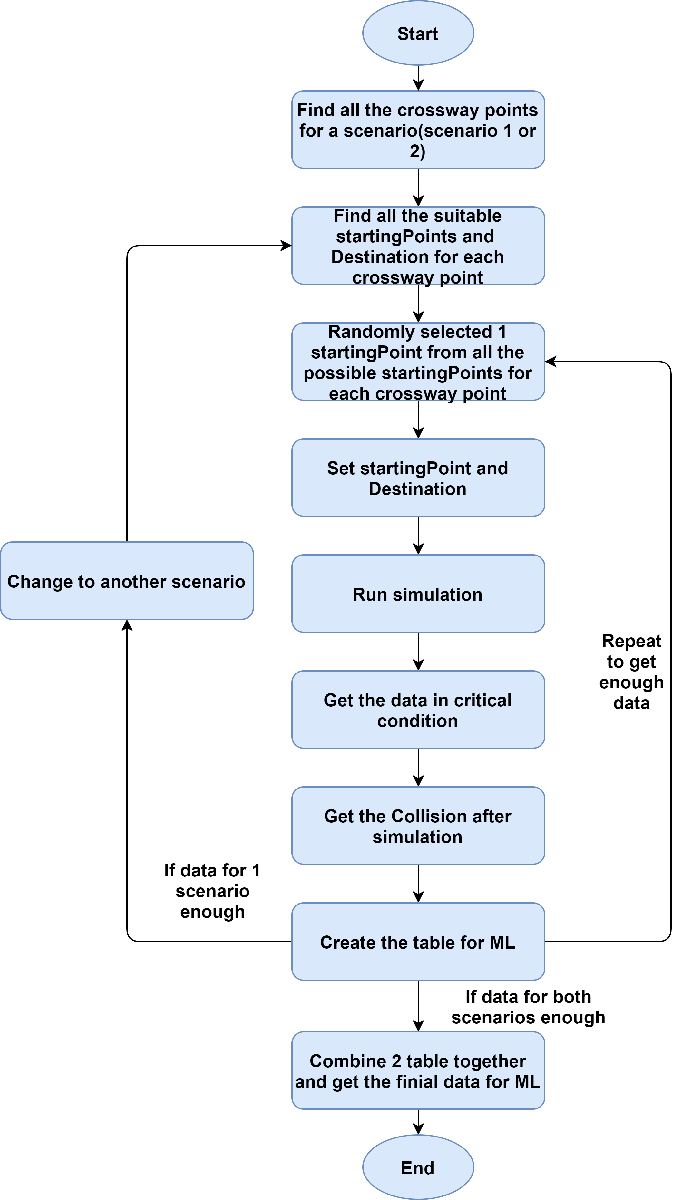

Firstly, we need to check the crossway point that we need to protect, they are Waypoint 11, 9, 13, 44, 4, 52, 36, 25, 23(see figure).

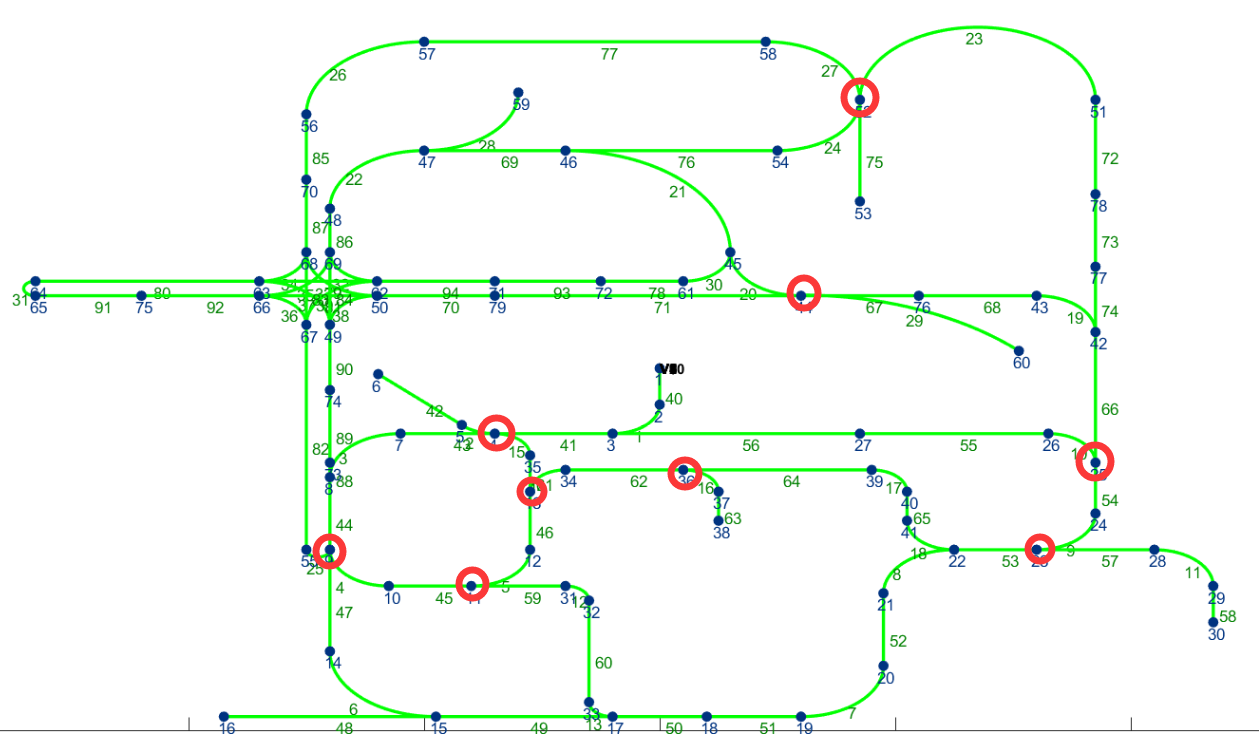

Since we have 10 vehicles, we can set 5 groups of vehicles and each group has two vehicles for one crossway point, then we can set two different scenarios to cover all the crossway points we need to protect, we should set the scenarios in the way that each group vehicles doesn't affect each other. So I choose the following crossway points as the scenarios:

- Scenario 1: Crossway point 11, 4, 36, 44, 25(Figure left)

- Scenario 2: Crossway point 9, 13, 52, 23(Figure right)

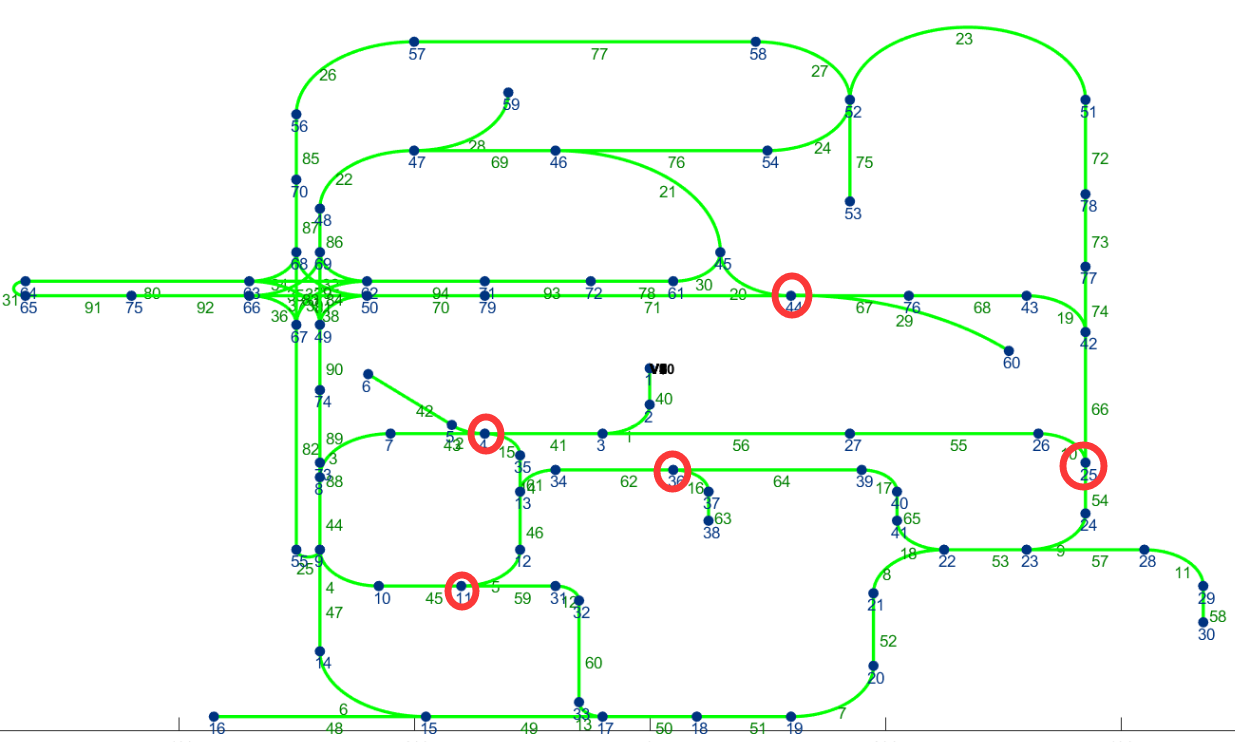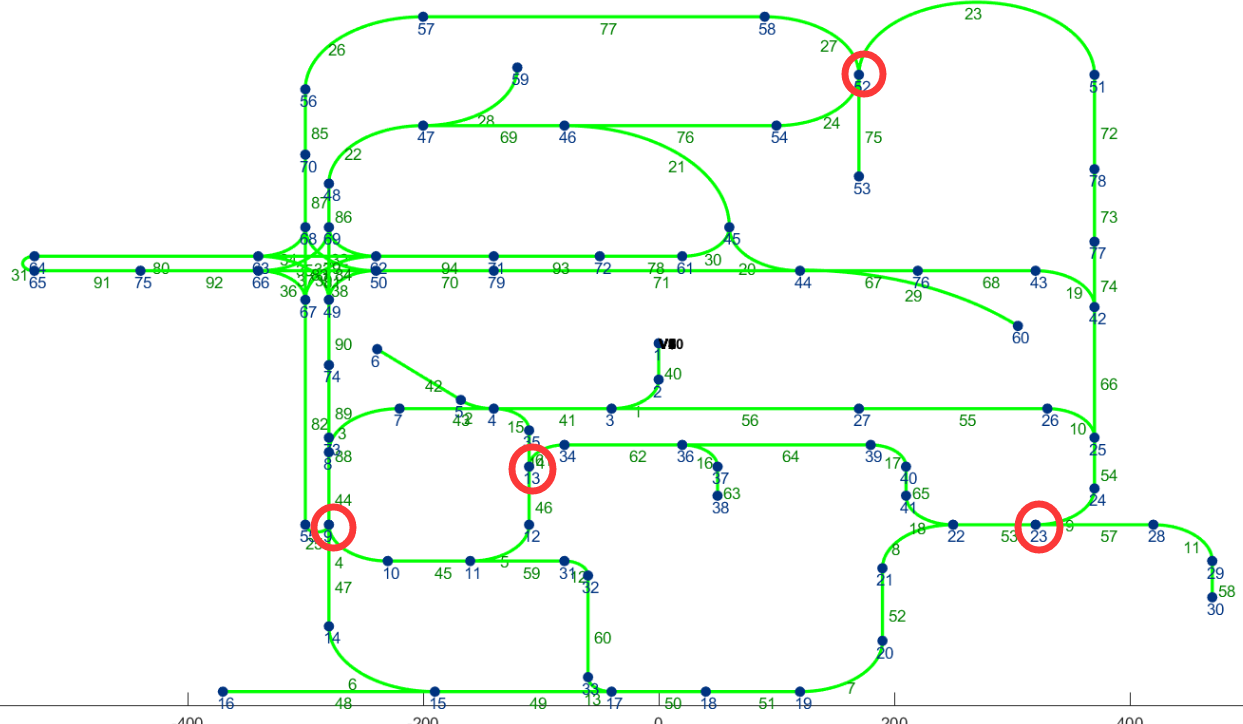

after choosing the crossway points for each scenario, the startingPoint and Destination can be defined based on the crossway point.

For the startingPoints, the vehicles need distance to accelerate to reach the maxSpeed, so we can't just choose the points very nearby the crossway point, for the startingPoint of each crossway point, it can be many different points, some are nearby the crossway point and some are far from the crossway point, all these cases may appear, an example is in the figure, for Path A, we can't only select the point 1(the nearest one) as the startingPoint because in this case, the speed of the vehicle can't reach the maxSpeed, we will miss some situations, only using the point 4 is also not good even if the vehicle can reach the maxSpeed when it starts here because we will miss some situations too, the vehicle can start at point 1, 2 or 3. So all the points(point 1, 2, 3, 4 in the figure) should be covered, and any point of them can be set as startingPoint, the way to do this is to set a vector, and put all the points we need in it, and then randomly select one of them as startingPoint, the process for Path B is the same.

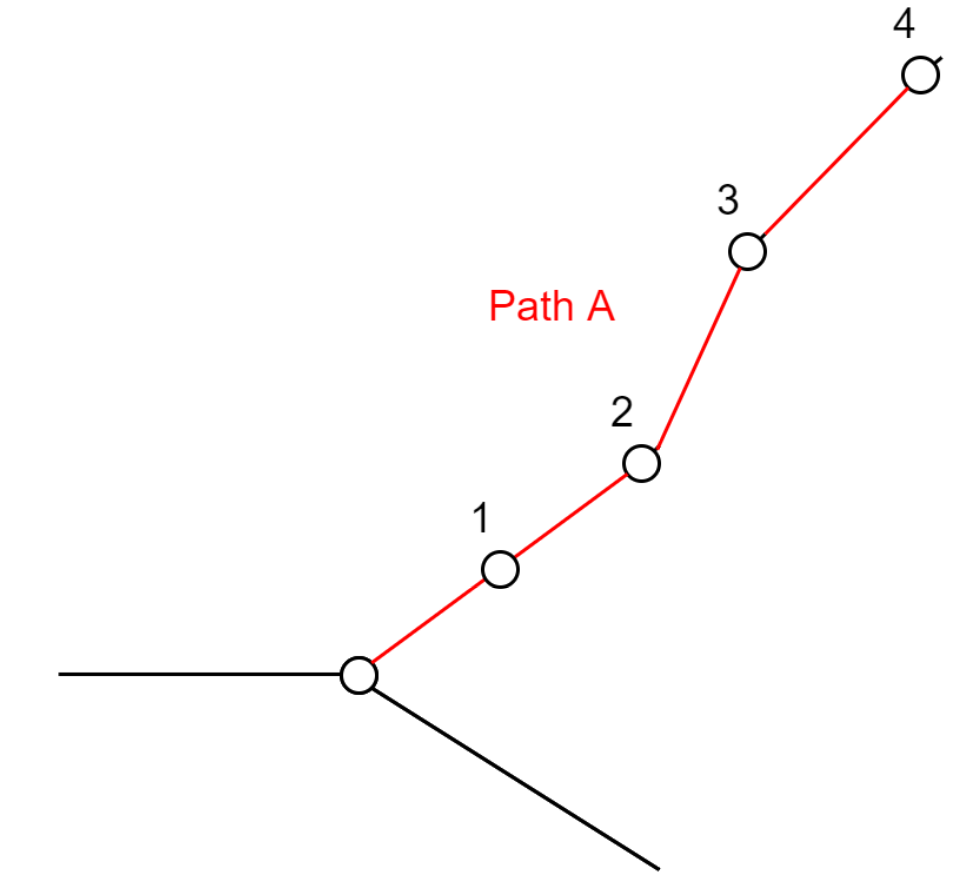

The Destination for Vehicle A and Vehicle B should not be too close,  or they might collide when they stop at the destination, which is not the situation we need. The way to avoid this is to set the Destination in route branch.

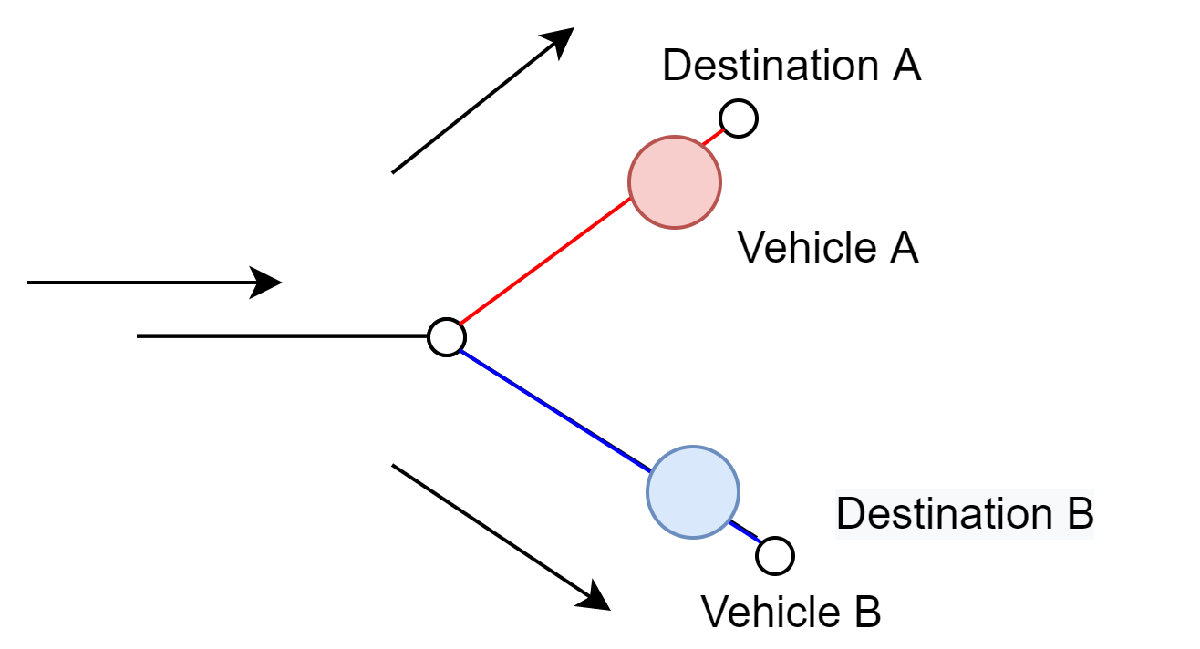

Other initial parameter are randomly set. 

The code for setting the initial parameter is here.

For the Crossway point 13, it's not easy to find a route branch and I find that the following collision(two vehicles collide in one path) often appear, so we can use the method before to collect the collision data only near the Crossway point 13. The related code is here. And also by creating table we need to pay attention on it, the related code is here.

For the Crossway point 9, we need to add more condiction as before. The related code is here, we should collect data for 9A and 9B sparetly, that means when we collect the data for Crossway point 9, we just choose one of them to collect, the other one should be comment and not run.

The data will still be obtained in critical condition and only collected one time when the vehicles are in critical condition.

In some situation, the startingPoint of the vehicles are already in the critical condiction and in this case, the data will be collect when the speed is still 0, so it won't be collected in the talbe, to avoid this, we can set a time shift at the beginning so that the vehicles will have a speed, the related code is here.

The Collision data will be obtained after the simulation, since we set the startingPoints and Destinations, the paths that vehicles will run are fixed, so the situation in the last 2 versions won't appear.

There are 4 files for data collection, the related files are in:

cd(currentPath + "\TrainModel\Version3\DataCollection")

**Version3_scenarios.m** is the file for setting the initial values, we have 2 scenarios with different initial startingPoint and Destination in this case, when we do simulation, we select one of the scenarios for each simulation and comment the other one. For scenario 2, we use a variable called Collision13 for the Crossway point 13 as mentioned before, so if we use scenario 1, we can comment this Collision13, and enable it when we use scenario 2.

**CollisionPredictor3.m** is the file for collecting the data during the simulation, when we use this way to get the data, we need to change line 11 in infrastructure.m to load this file. In this case, we have 2 scenarios, so make sure that the scenario is the same as Version3_scenarios.m.

**Version3_preprocess.m** is the file for creating the table for machine learning, it obtains the collision data after the simulation, and it also deletes the Vehicle ID for the table created in CollisionPredictorV3. For scenario 1, I use Data.mat to collect data, and for scenario 2, I use Data1.m to collect data, line 4, 8, 38, 44 are related to it. For scenario 2, the collision data for Crossway point 13 will be collected by variable Collision13, so by scenario 2, we enable line 27-31 and comment line 35, for scenario 1, we comment line 27-31 and enable line 35.

**Version3_run.m** is the file that set a loop for collecting the data so that we can get a large number of data easily.

The dataset I got are

cd(currentPath + "\TrainModel\Version3\Data")
load('Data.mat')

acc = 0.9718

load('Data1.mat')

and we can combine them with

Data2 = [Data;Data1];

To go back to Table of Contents

#### **Preprocess Data and Train Model**

This part is similar with the corresponding part in Model Version 1.

To go back to Table of Contents

#### **Evaluate Model**

The accuracy with cross-validation is good enough, Random Forest shows 95.3% accuracy.

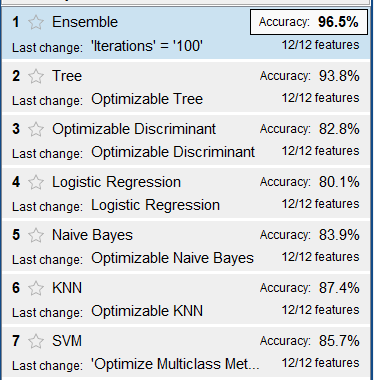

Use the testing data to test the Random Forest model, the accuracy is also good.

[Predict,score] = predict(Version3_1RF.ClassificationEnsemble,dataTest);
acc = nnz(Predict == dataTest.collision)/ numel(dataTest.collision)

To go back to Table of Contents

#### Feature Selection

Like the feature selection in Model Version 1, we use the importance of features in Random Forest, the Pareto chart shows the most important 8 features, we can see that the result are as expected, the most important 6 features are DistancetoCrosswaypoint, maxSpeed, and Speed for both vehicles. From the Pareto chart, we can know that the first 6 features have around 75% contribution for the collision prediction, we can take these 6 features to train a model with fewer features to reduce the calculation requirement.

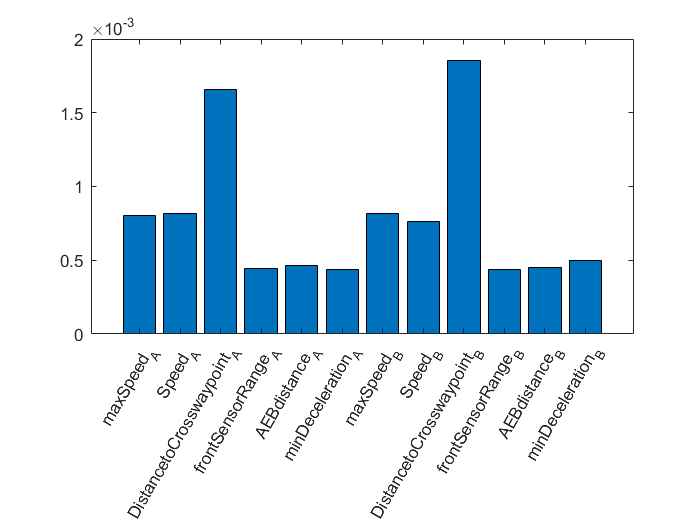

p0 = predictorImportance(Version3_1RF.ClassificationEnsemble);

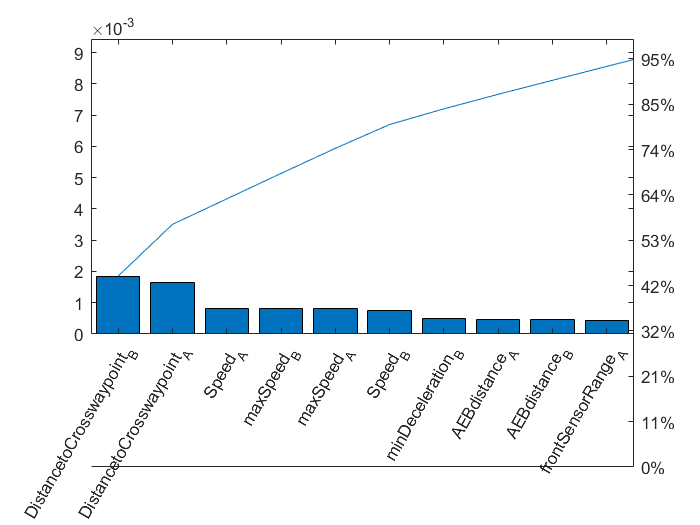

%bar chart
bar(p0)
xticklabels(Data2.Properties.VariableNames(1:end-1))
xtickangle(60)


% pareto chart
pareto(p0,Data2.Properties.VariableNames(1:end-1))
xtickangle(60)

To go back to Table of Contents

#### **Train Model with Selected Features**

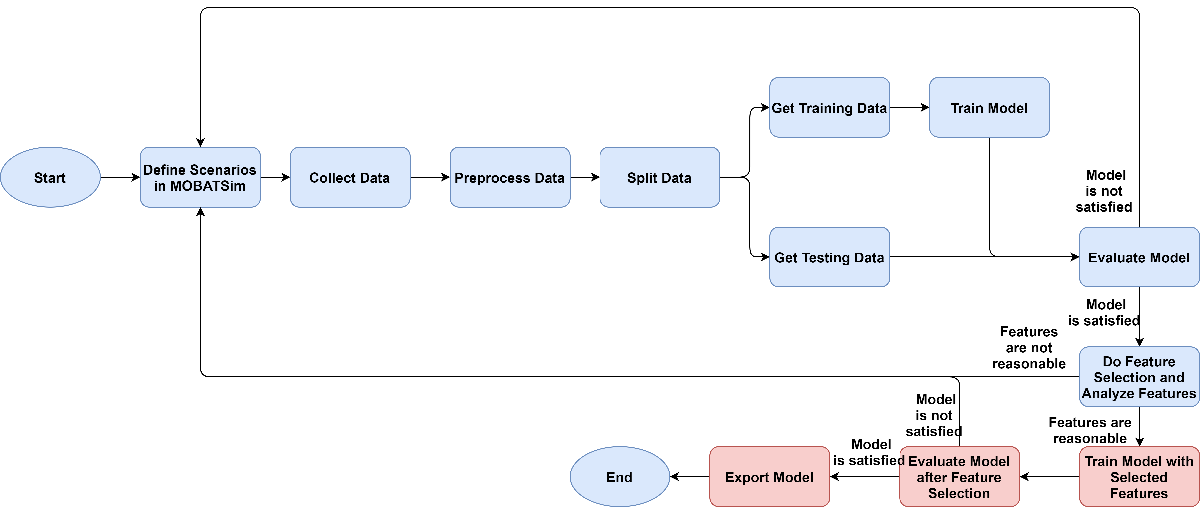

Now we can train a new model with the following features:

- maxSpeed_A

- Speed_A

- DistancetoCrosswaypoint_A

- maxSpeed_B

- Speed_B

- DistancetoCrosswaypoint_B

we just need to delete the ranks of other features in the table we get before, or directly use the Classification APP in MATLAB to choose these 6 features to train a Random Forest model. Here I use the Classification Learner APP.

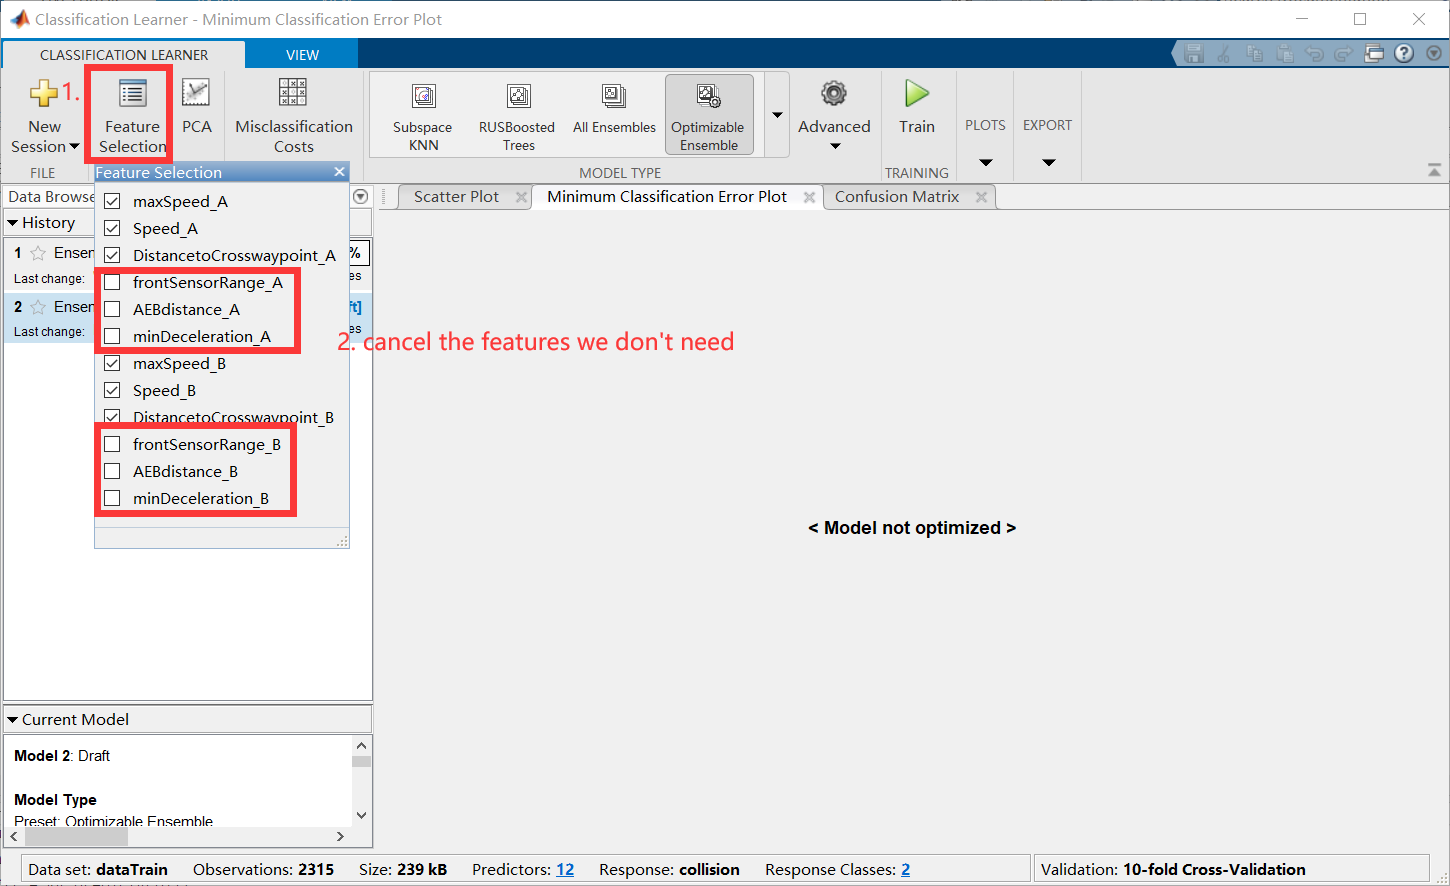

after setting the feature selection option, we can train the model as train model process before. The random forest model after feature selection has a accuracy with 96.8%.

To go back to Table of Contents

#### **Conclusion**

The accuracy and the importance of features are as expected, this model will be suitable for collision prediction at the crossway point.

To go back to Table of Contents

## **B Implement the Predictor**

### 1.Design of the Predictor

The workflow of the predictor is shown in the figure.

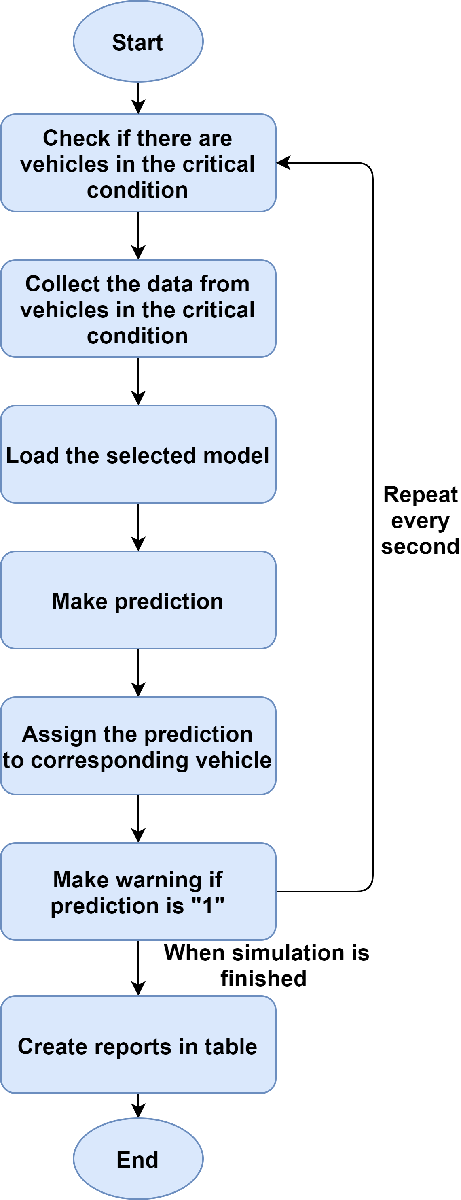

The predictor will be used for different scenarios, so it should be able to find the critical condition for all the crossway points, the way to do this is the same as the method to find the the Path A and Path B before, and it will only make predictions when the vehicles are still run(not collide or reach the destination). It will check the situation every second, to not slow down the simulation speed too much. The related code is here.

After getting the data in critical conditions, it will use the trained model to make prediction every second, the prediction is for Vehicle A and Vehicle B both in a row of the table, the prediction can be assigned to the corresponding vehicle according to the Vehicle ID, the prediction for each second will be collected in a table. If there are more than two vehicles in the critical condition, the predictor will predict for all the possible combination of vehicles, for example, in the following figure, it will predict for Vehicle 1 and Vehicle 2, Vehicle 1 and Vehicle 4, Vehicle 3 and Vehicle 2, Vehicle 3 and Vehicle 4. And for each vehicle, if one of those prediction shows that this vehicle will collide, the predictions for this vehicle will be "1"(collide). The related code is here.

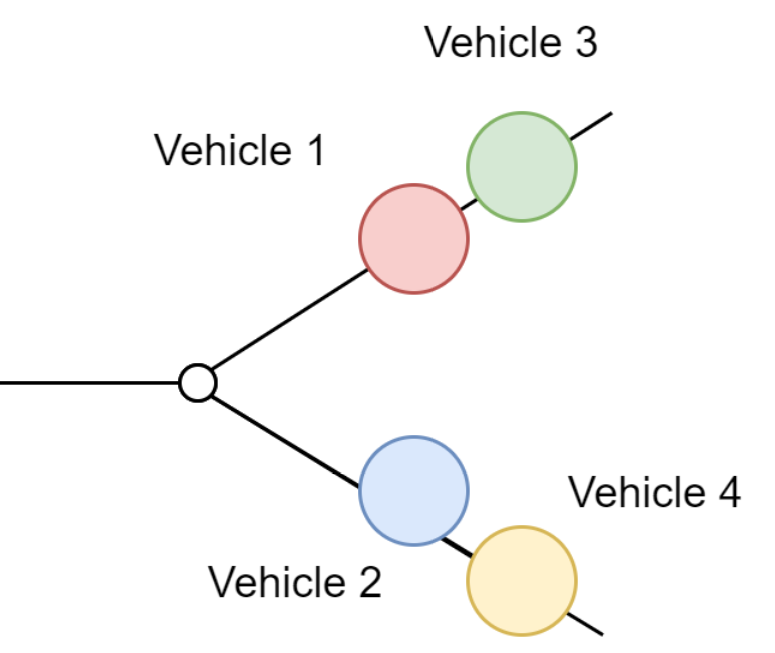

If the prediction shows there will be a collision, it will display a warning in the command window. The related code is here.

After the whole simulation, it will create two reports in table form("Warning" and "Status"), for both table, the rows mean the time, the rank means the Vehicle ID.  "Warning" is the table of prediction, 0 means there won't be a collision, 1 means there will be a collision, 2 means the predictor doesn't predict at that time. "Status" is the table of the true situation,  0 means there isn't a collision, 1 means there is a collision.

The difference bewteen the predictor before feature selection and after feature selection are:

- Use the different machine learning models.

- By collecting the input data for predicting, the predictor after feature selection collects the subset of the data that the predictor before feature selection collects.

The related files are in:

cd(currentPath + "\Predictor");

ans = 0.0289

There are 2 predictor, one is before feature selection, one is after feature selection.

To go back to Table of Contents

### 2.Use the Predictor

To run simulation with the predictor, just enable the line 11, 26, 69 in infrastructure.

If you want to change the predictor, change line 11 in infrastructure to select CollisionPredictor 1 or 2, CollisionPredictor 1 is the predictor before feature selection(with 12 features), CollisionPredictor 2 is the predictor after feature selection(with 6 features).

If you want to change the model for predictor, change model name line 48 and 288 in CollisionPredictor 1 or  line 48 and 210 in CollisionPredictor 2, make sure that the model has the same features as the predictor. 

If you want to change the sample time, change line 42 in CollisionPredictor1 or CollisionPredictor 2.

# **II Validation**

## **A Model before Feature Selection**

In this part we evaluate the performance of the model before doing the feature selection, that means the model use the following features:

- maxSpeed_A

- frontSensorRange_A

- ABEdistance_A

- minDeceleration_A

- Speed_A

- DistancetoCrosswaypoint_A

- maxSpeed_B

- frontSensorRange_B

- ABEdistance_B

- minDeceleration_B

- Speed_B

- DistancetoCrosswaypoint_B

"A" and "B" mean data from Vehicle A and Vehicle B as we defined the critical condiction.

To go back to Table of Contents

### **1. Confusion Matrix**

The confusion matrix is a tool to evaluate the performance of a classification machine learning model, the rank of the matrix represents the predict class, the row of the matrix represents the true class, with confusion matrix we can compare the predict results and real situations easily and get a good evaluation of the model. The figure shows the confusion matrix of the model with all the features by training the model with 10-fold cross-validation, we can directly obtain it after we train the model in the Classification Learner APP. The diagonal of the matrix is the correct prediction, what we need to focus on are the wrong predictions, they are:

- Predicted Class is "1"  and True Class is "0": this is the situation that predictor predicts a collision but it actually doesn't happen, it's a wrong but not serious, because nothing serious happens in fact.

- Predicted Class is "0"  and True Class is "1": this is the situation that predictor predicts no collision but it actually happens, it's wrong and it is serious, because the collision is not predicted, it will cause loss if it is not a simulation but in reality. 

There 48 worst cases, so the fatal case account for 2.89%.

67/(1842 + 18 + 67 + 388)

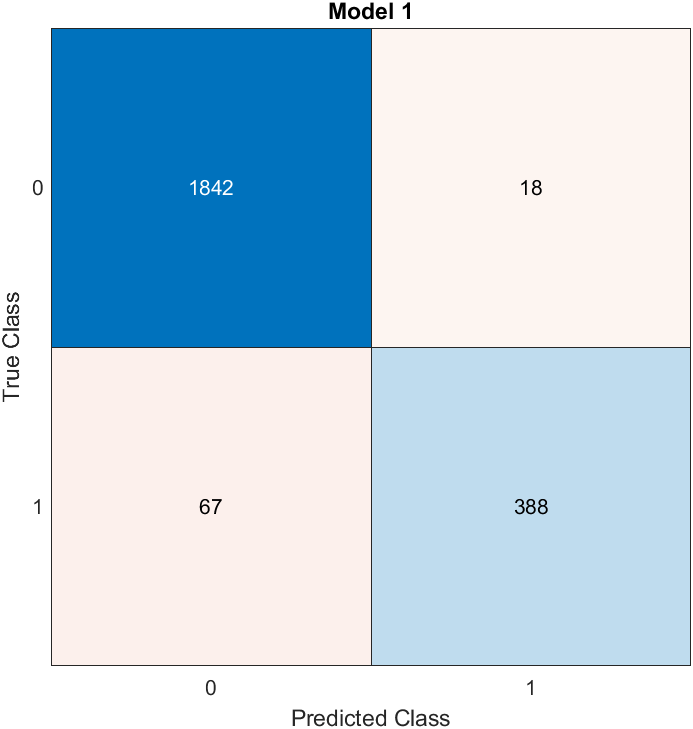

we can also use the test dataset to make a confusion matrix:

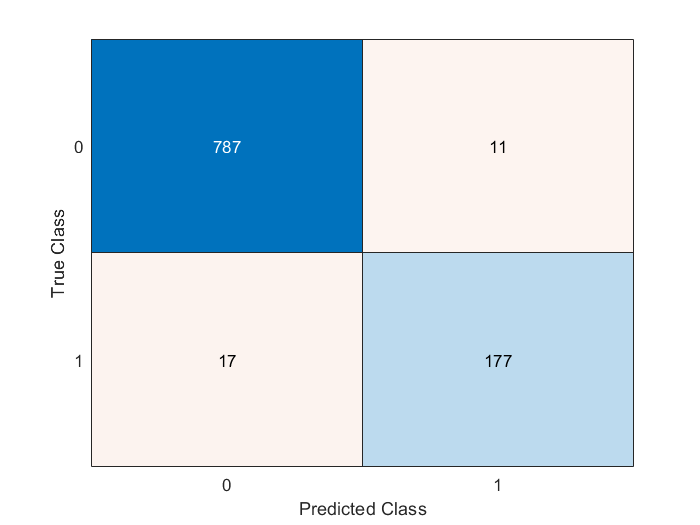

predictions = predict(Version3_1RF.ClassificationEnsemble,dataTest);

confusionchart(dataTest.collision,predictions)

For the fatal case(Predicted Class is "0"  and True Class is "1") account for 1.71%.

17/(787 + 11 + 17 + 177)

ans = 0.0171

Both results are acceptable, but can still be improved.

To go back to Table of Contents

To go back to Model after Feature Selection

### **2. Some Example of Testing**

#### Warning

Here is an example of warning,  the predictor predicts that Vehicle 5 and 6 will collide, 

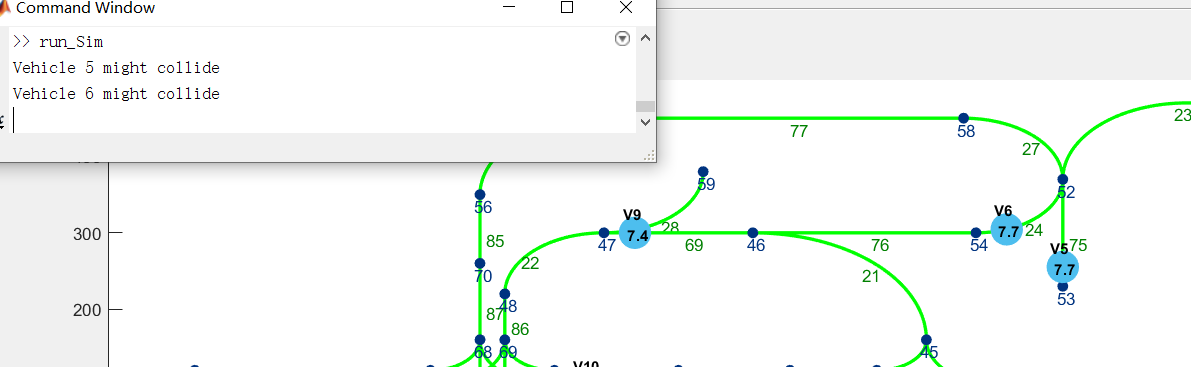

and then they collide together.

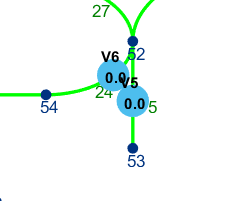

To go back to Table of Contents

#### Report

Here is an example of reports, the figure left is the prediction, it predicts Vehicle 5 and 6 at the first 2 seconds, and they collied later, it also predicts Vehicle 1 and 2, Vehicle 7 and 8 won't collide, and they don't. At other times, the predictor doesn't make any prediction.

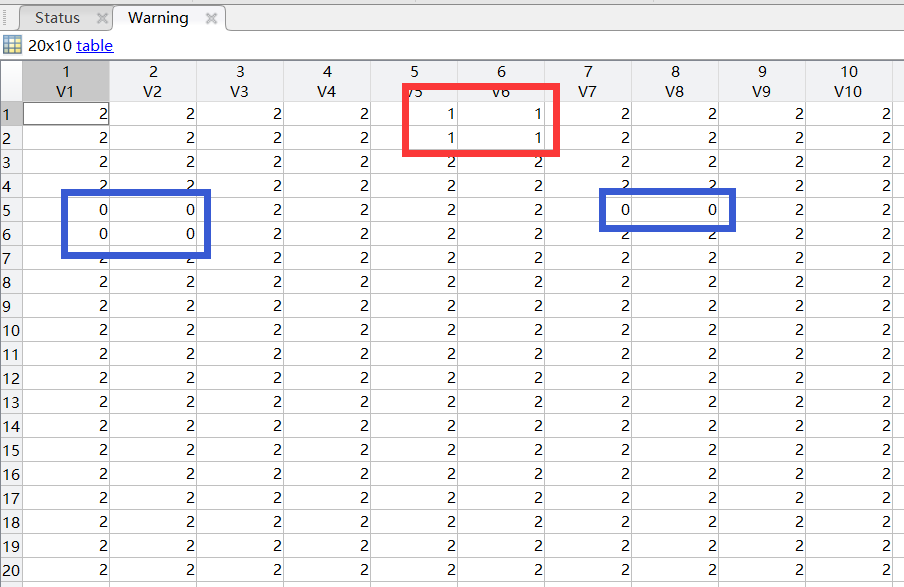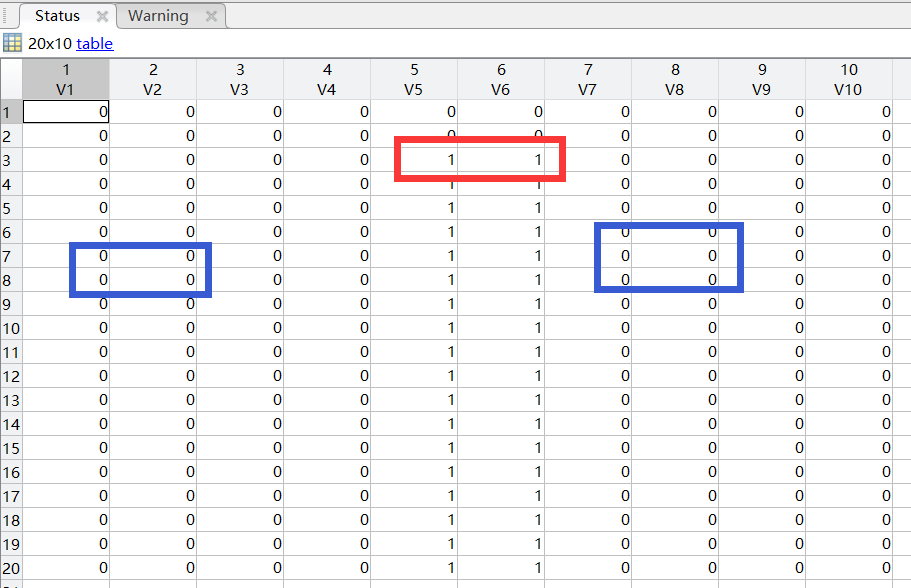

To go back to Table of Contents

## **B Model after Feature Selection**

In this part we evaluate the performance of the model before doing the feature selection, that means the model use the following features:

- maxSpeed_A

- Speed_A

- DistancetoCrosswaypoint_A

- maxSpeed_B

- Speed_B

- DistancetoCrosswaypoint_B

"A" and "B" mean data from Vehicle A and Vehicle B as we defined the critical condition.

To go back to Table of Contents

### 1. Confusion Matrix

The figure shows the confusion matrix of the model with all the features by training the model with 10-fold cross-validation. Like I mention in the part of the model before feature selection, we need to focus on the situation that Predicted Class is "0"  and True Class is "1", the worst case.

There 48 worst cases, so the fatal case account for 2.07%.

48/(1834 + 26 + 48 + 407)

ans = 0.0207

the result is better than the model before feature selection, this means the features after feature selection is very important and some other features might not be important for road merge collision prediction and impact the model.

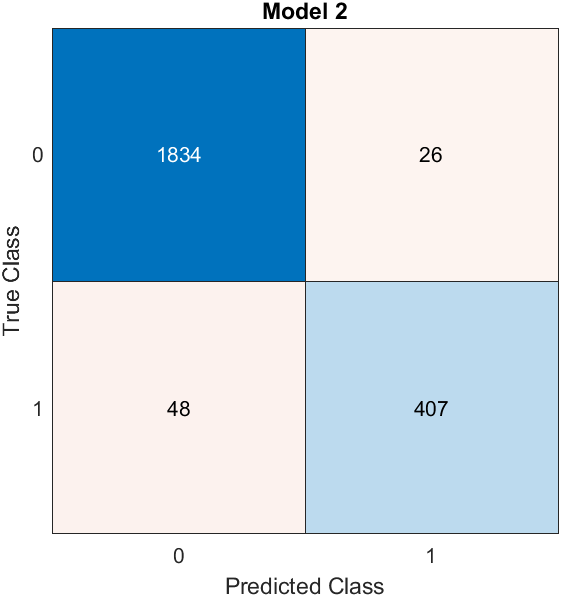

we can also use the test dataset to make a confusion matrix:

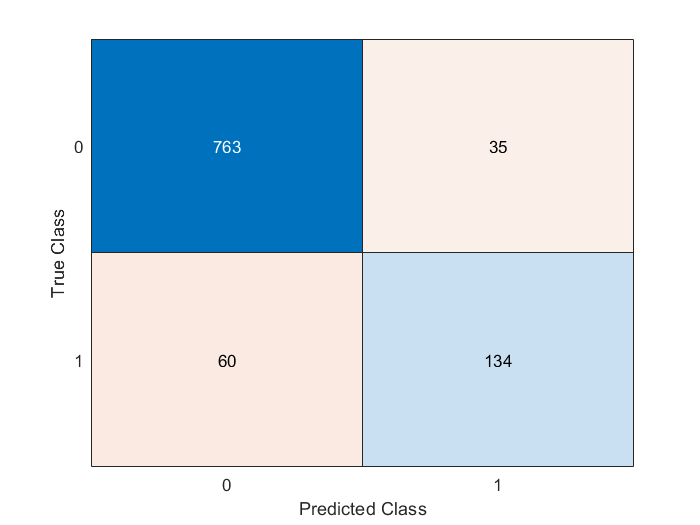

predictions = predict(Version3_2.ClassificationEnsemble,dataTest);
confusionchart(dataTest.collision,predictions)

For the fatal case(Predicted Class is "0"  and True Class is "1") account for 6.05%.

60/(763 + 35 + 60 + 134)

ans = 0.0605

Both results are acceptable.

To go back to Table of Contents

### **2. Some Example of Testing**

#### Warning

Here is an example of the predictor using the model with the reduced features, we can see it predicted that Vehicle 1 and Vehicle 2 will collide

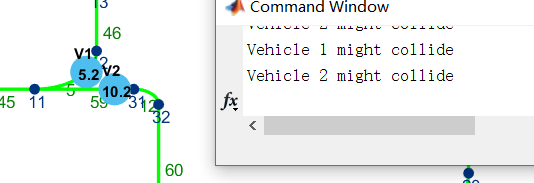

, and they collided later.

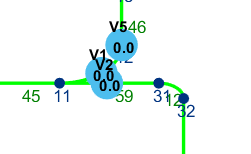

#### **Report**

Here is an example of reports, the figure left is the warning table, we can see at the first 3 seconds the predictor predicted Vehicle 1 and Vehicle 2 will collide, and at the 4th second they collided(the red frame), and it also predicts for other vehicles at different times when they are in the critical condition, and the predictions show that they won't collide, and they did not collide.

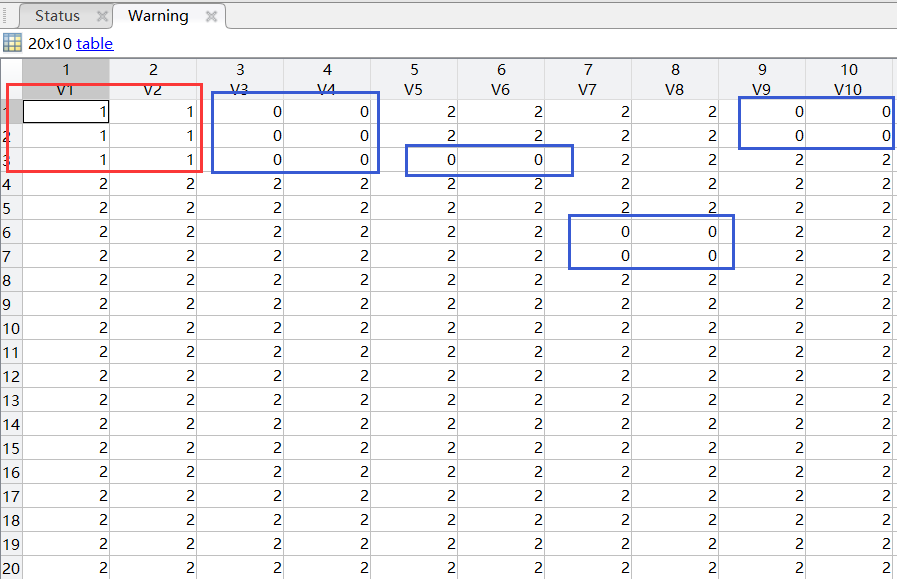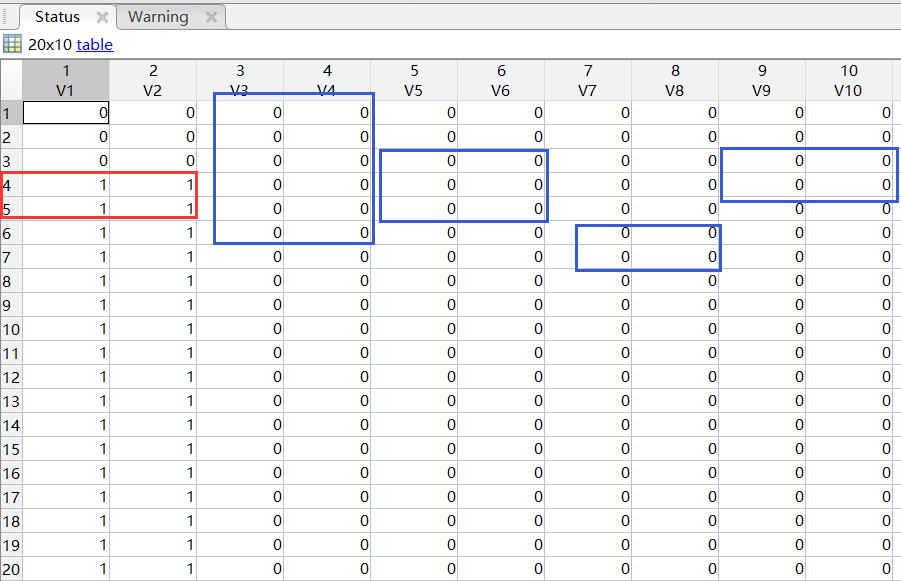

# **III Code**

## **A Data Collection for Version 1**

### **1. Define Scenario**

To go back to Table of Contents

To go back to Model Version 1

To go back to Table of Contents

To go back to Model Version 1

### **2. Collect Data**

To go back to Table of Contents

To go back to Model Version 1

To go back to Table of Contents

To go back to Model Version 1

### **3. Create Table**

To go back to Table of Contents

To go back to Model Version 1

## **B Data Collection for Version 2**

### **1. Define Scenario**

To go back to Table of Contents

To go back to Model Version 2

To go back to Table of Contents

To go back to Model Version 2

### **2. Collect Data**

To go back to Table of Contents

To go back to Model Version 2

To go back to Table of Contents

To go back to Model Version 2

To go back to Table of Contents

To go back to Model Version 2

To go back to Table of Contents

To go back to Model Version 2

### **3. Create Table**

To go back to Table of Contents

To go back to Model Version 2

## **C Data Collection for Version 3**

### **1. Define Scenario**

To go back to Table of Contents

To go back to Model Version 3

To go back to Table of Contents

To go back to Model Version 3

To go back to Table of Contents

To go back to Model Version 3

To go back to Table of Contents

To go back to Model Version 3

### **2. Collect Data**

To go back to Table of Contents

To go back to Model Version 3

To go back to Table of Contents

To go back to Model Version 3

To go back to Table of Contents

To go back to Model Version 3

To go back to Table of Contents

To go back to Model Version 3

To go back to Table of Contents

To go back to Model Version 3

### **3. Create Table**

To go back to Table of Contents

To go back to Model Version 3

To go back to Table of Contents

To go back to Model Version 3

To go back to Table of Contents

To go back to Model Version 3

## D Predictor **before Feature Selection**

To go back to Table of Contents

To go back to Implement the Predictor

To go back to Table of Contents

To go back to Implement the Predictor

To go back to Table of Contents

To go back to Implement the Predictor

## **E Predictor after Feature Selection**

To go back to Table of Contents